clear
clc
dataset= importdata('ballbearings.txt');

# **PROGETTO TAGLIALATELA**

Il dataset scelto è quello dei cuscinetti a sfera. Nel dataset sono presenti dati provenienti da 3 aziende diverse, l'analisi verrà effettuata per ognuna. Il dataset è composto da 210 osservazioni. (FONTE: Lieblein, J., and Zelen, M. (1956), “Statistical investigation of the fatigue life of deep-groove ball bearings”)

## Classificazione dati

Dal file di testo relativo al dataset sono riportate le informazioni riguardo alle variabili d'interesse. Si procederà a suddividerle in vettori. Ci sono, inoltre, alcuni dati mancanti (gli anni dei test numero 44-49 dell'azienda 1), che non verranno usati nell'analisi.

company = dataset(:,1); 
test = dataset(:,2); 
year = dataset(:,3); %9999 per il dato mancante
bearings_number = dataset(:,4); %cuscinetti testati
load = dataset(:,5);
balls_number = dataset(:,6);
diameter = dataset(:,7);
L10 = dataset(:,8); 
L50 = dataset(:,9);
Weibull_slope = dataset(:,10); 
Bearing_type = dataset(:,11); 

## Vita a fatica

Il modello matematico che ci permette di prevedere la vita a fatica per un cuscinetto a sfera, con grado di affidabilità 90% è il seguente (ISO 281):

$L_{10h} =\frac{{10}^6 }{60N}$ ${\left(\frac{C}{P}\right)}^p$ , dove:

- N = velocità di rotazione in esercizio in rpm

- C = coefficiente di carico dinamico

- P = carico equivalente

- p = coefficiente che dipende dal tipo di cuscinetto (per quelli a sfera p=3)

# **ANALISI PRELIMINARE - Statistica descrittiva**

In questa sezione verranno presentati i dati raccolti, usando i metodi ritenuti più adeguati in base al tipo di dato.

## **Cuscinetti/azienda**

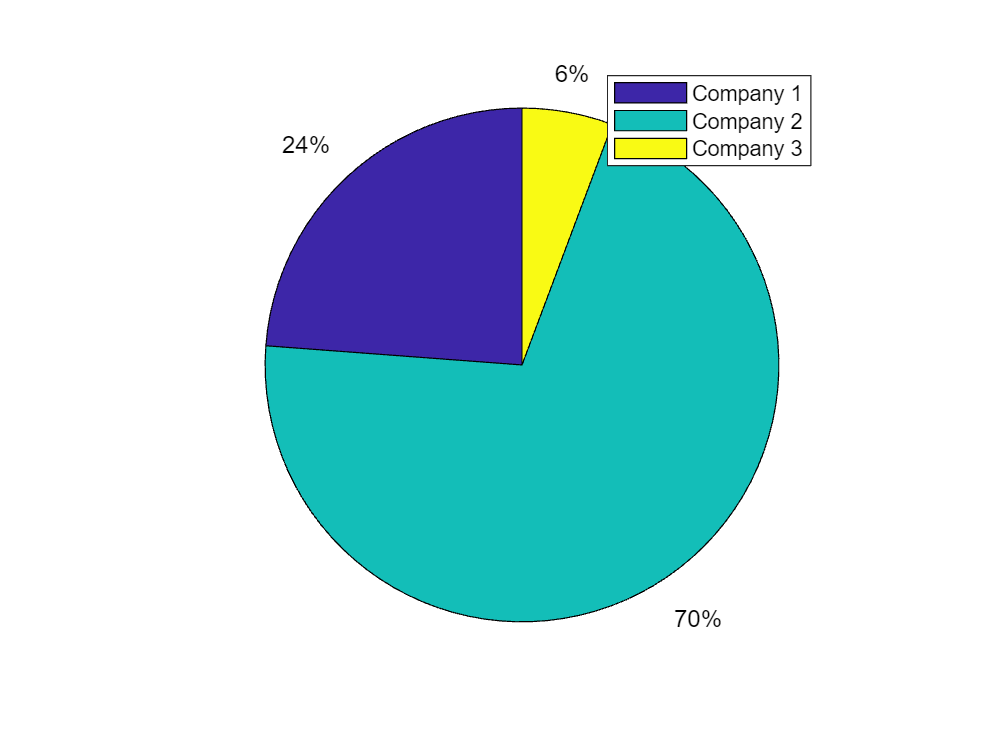

labels= {'Company 1','Company 2','Company 3'};
tab1= tabulate(company);
tab1= tab1(:,3);
pie(tab1), legend(labels)

## Diametri

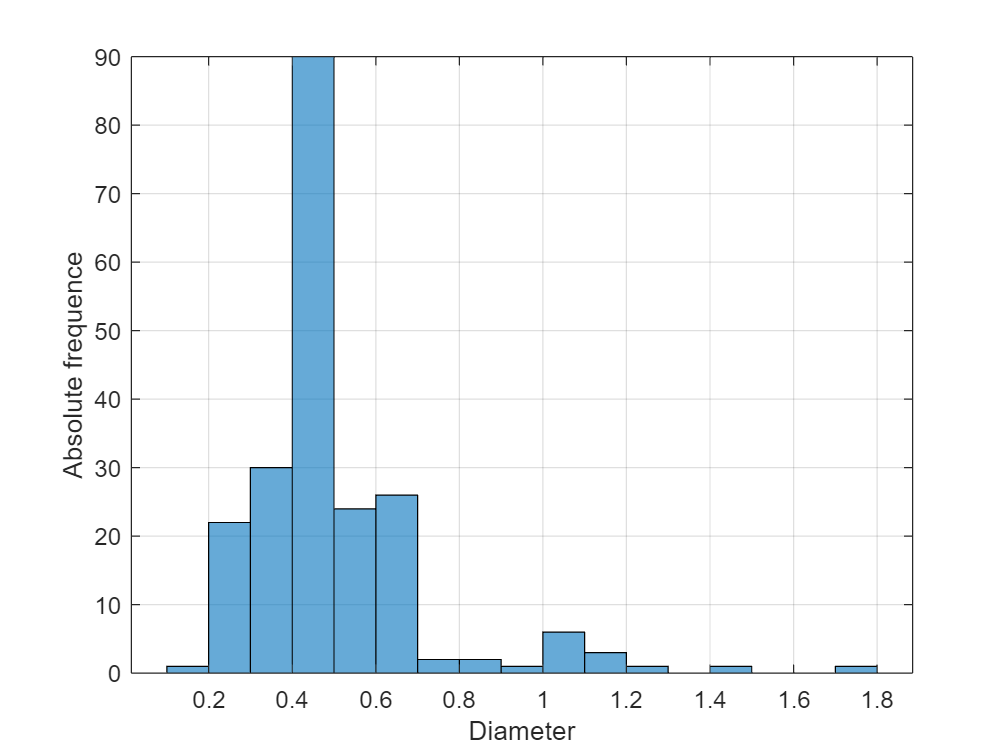

histogram(diameter), xlabel('Diameter'), ylabel('Absolute frequence'), grid on

Dmin= min(diameter)

Dmin = 0.1875

Dmax= max(diameter)

Dmax = 1.7500

Davg= mean(diameter)

Davg = 0.5056

Dstd= std(diameter)

Dstd = 0.2226

## Numero di sfere

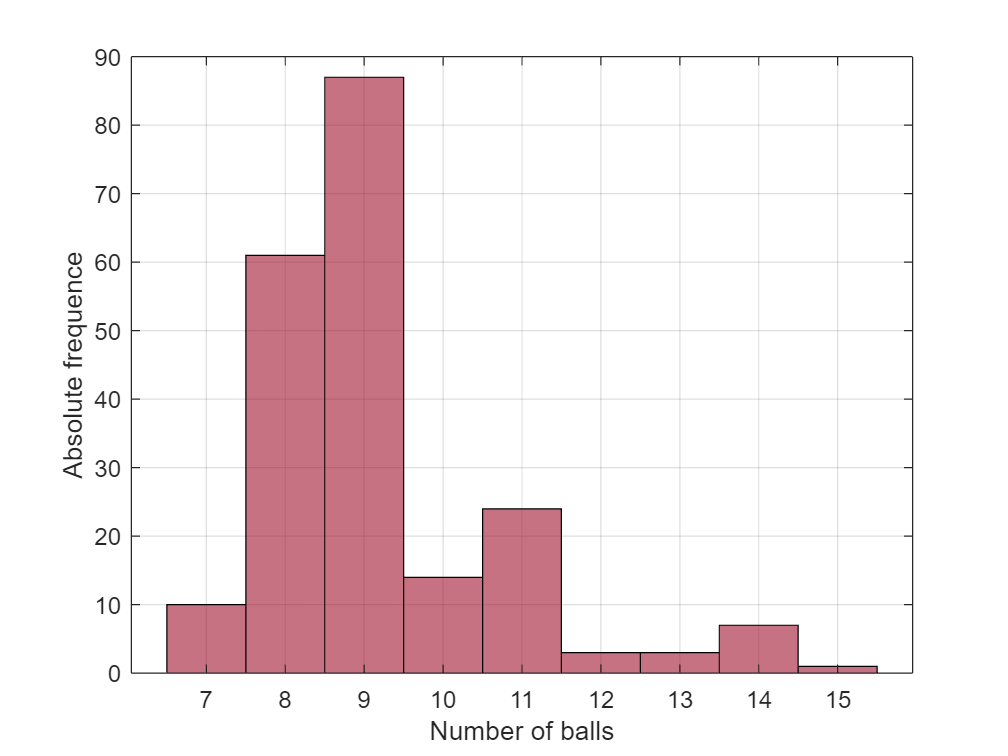

histogram(balls_number,'FaceColor',"#A2142F"), xlabel('Number of balls'), ylabel('Absolute frequence'), grid on

Zmin= min(balls_number)

Zmin = 7

Zmax= max(balls_number)

Zmax = 15

Zavg= mean(balls_number)

Zavg = 9.2048

Zstd= std(balls_number)

Zstd = 1.5284

## Durate:

### L10 - 90% success rate

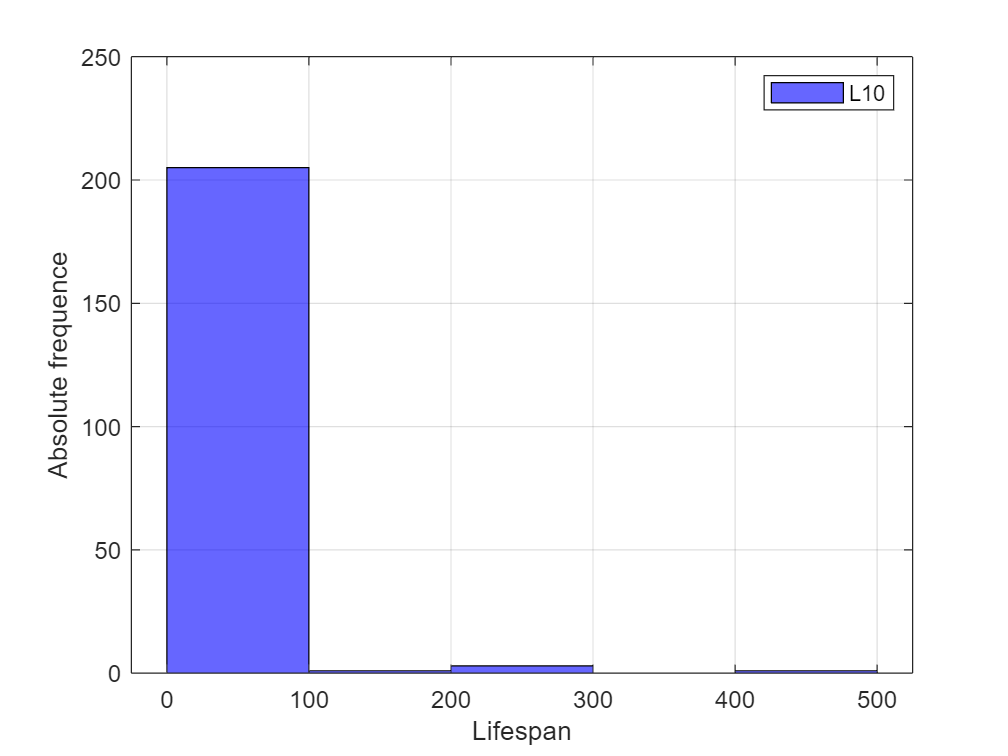

histogram(L10,'binwidth',100,'Facecolor','b'), grid on, xlabel('Lifespan'), ylabel('Absolute frequence'), hold on
legend('L10'), hold off

L10min= min(L10)

L10min = 0.8830

L10max= max(L10)

L10max = 417

L10avg= mean(L10)

L10avg = 21.3608

L10std= std(L10)

L10std = 41.0540

### L50 - 50% success rate

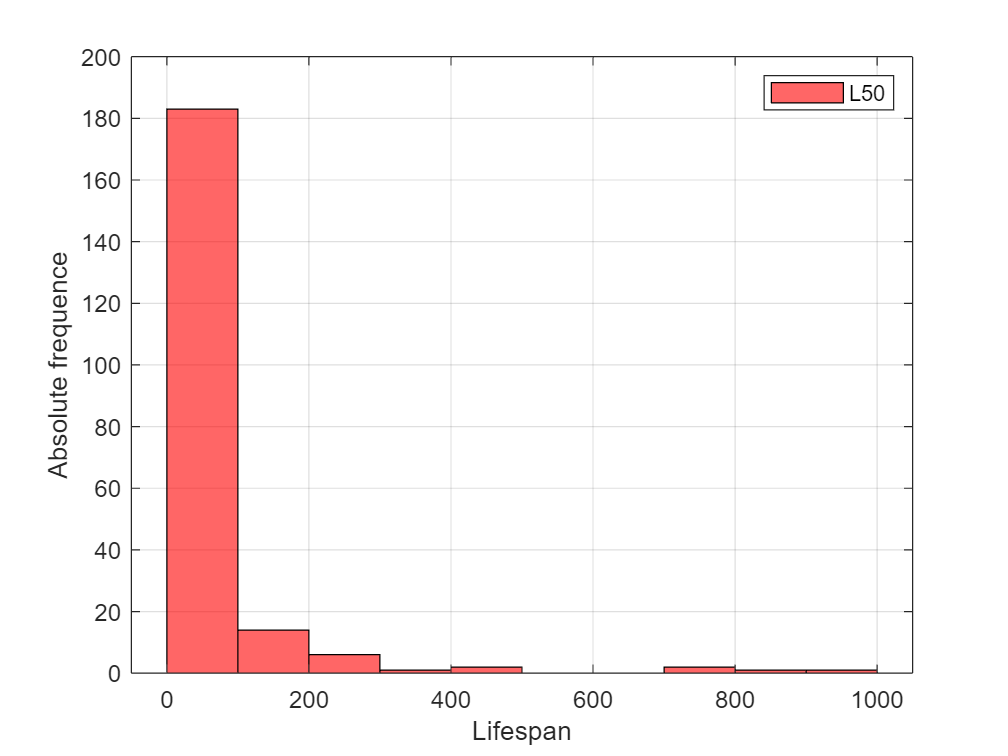

histogram(L50,'binwidth',100,'Facecolor','r'), grid on, xlabel('Lifespan'), ylabel('Absolute frequence'), hold on
legend('L50'), hold off

L50min= min(L50)

L50min = 3.2300

L50max= max(L50)

L50max = 951

L50mean= mean(L50)

L50mean = 76.9184

L50std= std(L50)

L50std = 120.4000

### Carico equivalente

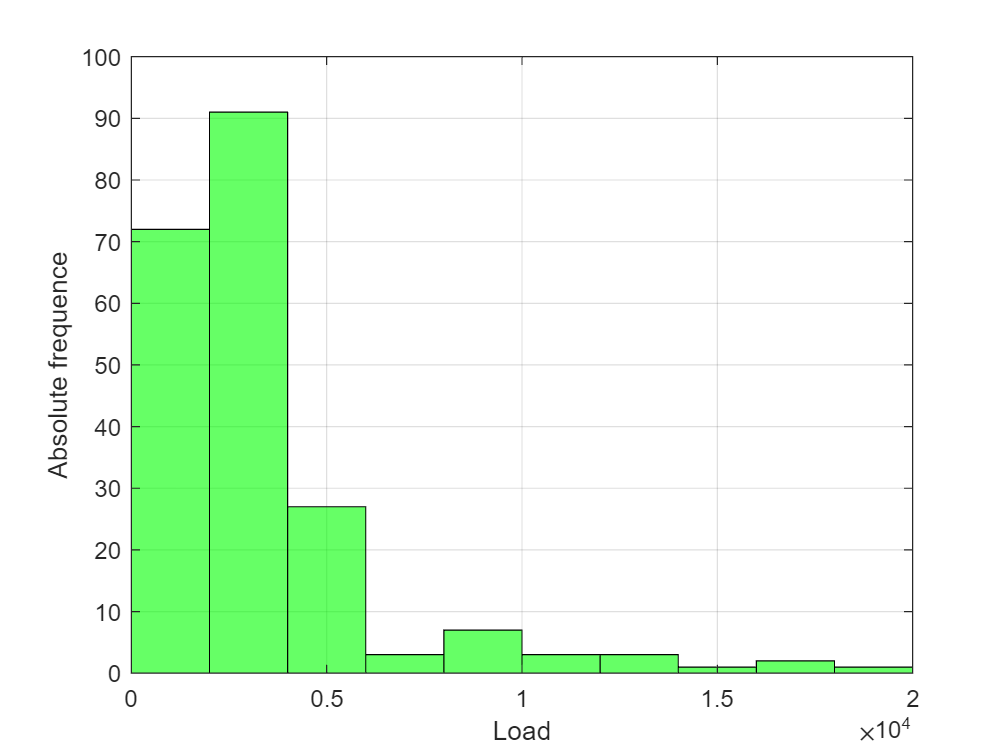

histogram(load,'binwidth',2000,'FaceColor','g'), grid on
xlabel('Load'), ylabel('Absolute frequence'), axis([0 20000 0 100])

Pmin= min(load)

Pmin = 565

Pmax= max(load)

Pmax = 19750

Pavg= mean(load)

Pavg = 3.0835e+03

Pstd= std(load)

Pstd = 2.9962e+03

## Scatter plot per le variabili

In questa sezione si usa la funzione *scatter(x,y,options)* per confrontare lo stesso dato ma di più aziende

### Carichi

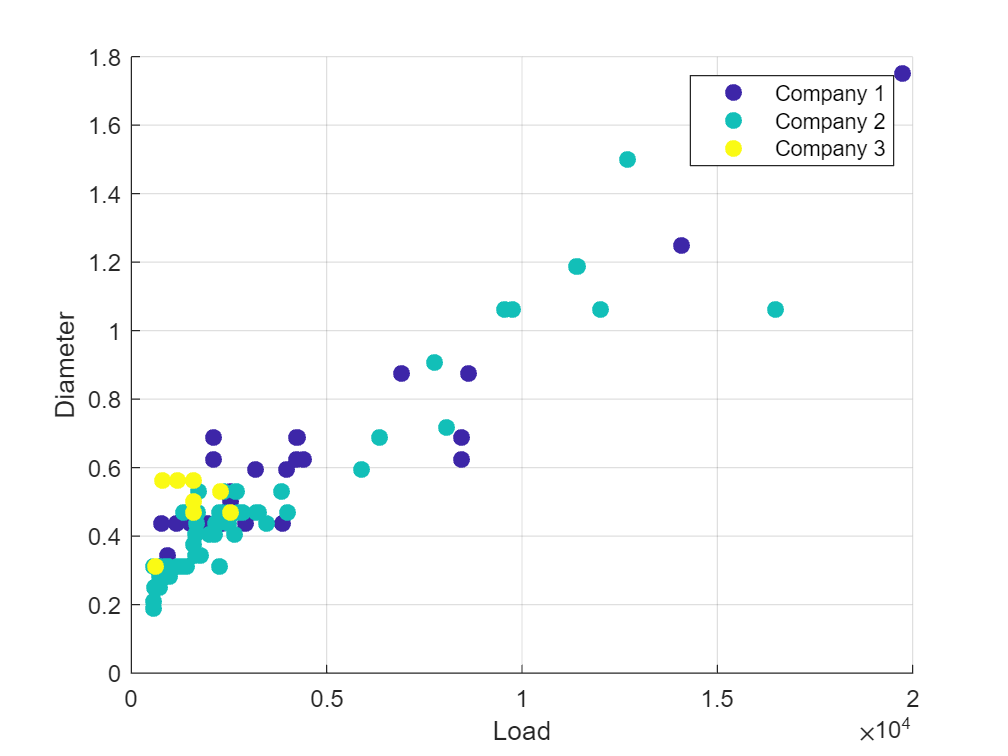

scatter(load(1:50,1),diameter(1:50,1), 'MarkerEdgeColor',[0.24 0.15 0.66],...
              'MarkerFaceColor',[0.24 0.15 0.66],...
              'LineWidth',1) %azienda 1
hold on
scatter(load(51:198,1),diameter(51:198,1), 'MarkerEdgeColor',[0.07 0.75 0.72],...
              'MarkerFaceColor',[0.07 0.75 0.72],...
              'LineWidth',1) %azienda 2
hold on
scatter(load(199:210,1),diameter(199:210,1), 'MarkerEdgeColor',[0.98 0.98 0.08],...
              'MarkerFaceColor',[0.98 0.98 0.08],...
              'LineWidth',1) %azienda 3
hold off
xlabel('Load'), ylabel('Diameter'), legend(labels), grid on

### Durate:

#### durata - carico

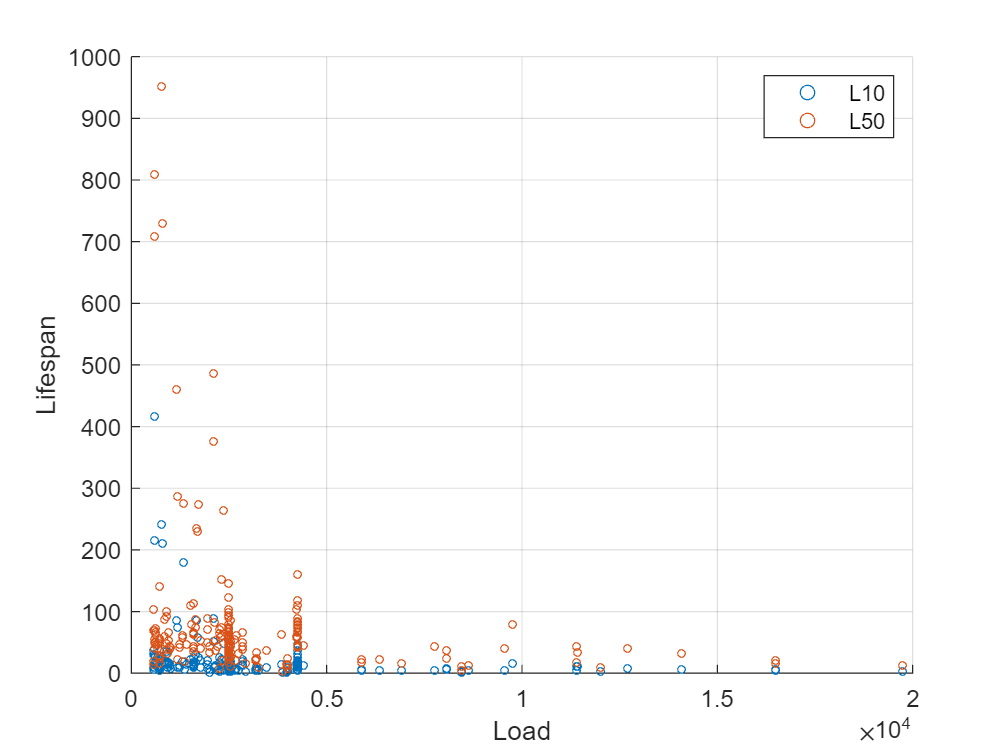

scatter(load,L10,10)
hold on
scatter(load,L50,10)
hold on
grid on
hold off
xlabel('Load'), ylabel('Lifespan'), legend('L10','L50')

#### durata - diametro

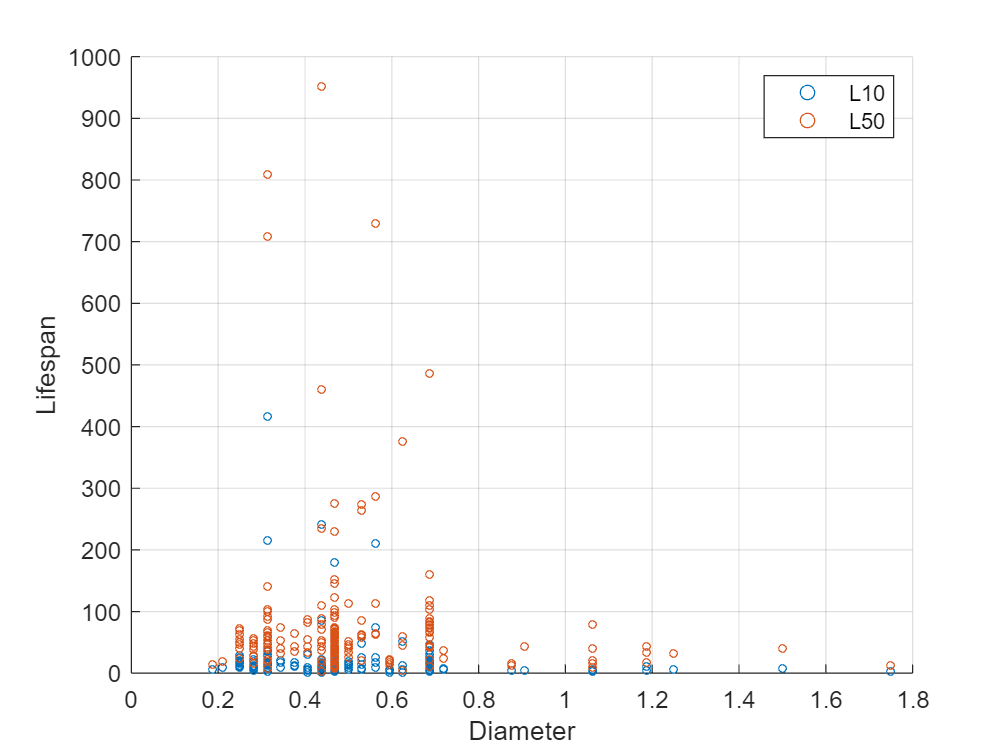

scatter(diameter,L10,10)
hold on
scatter(diameter,L50,10)
hold on
grid on
hold off
xlabel('Diameter'), ylabel('Lifespan'), legend('L10','L50')

#### durata - numero di sfere

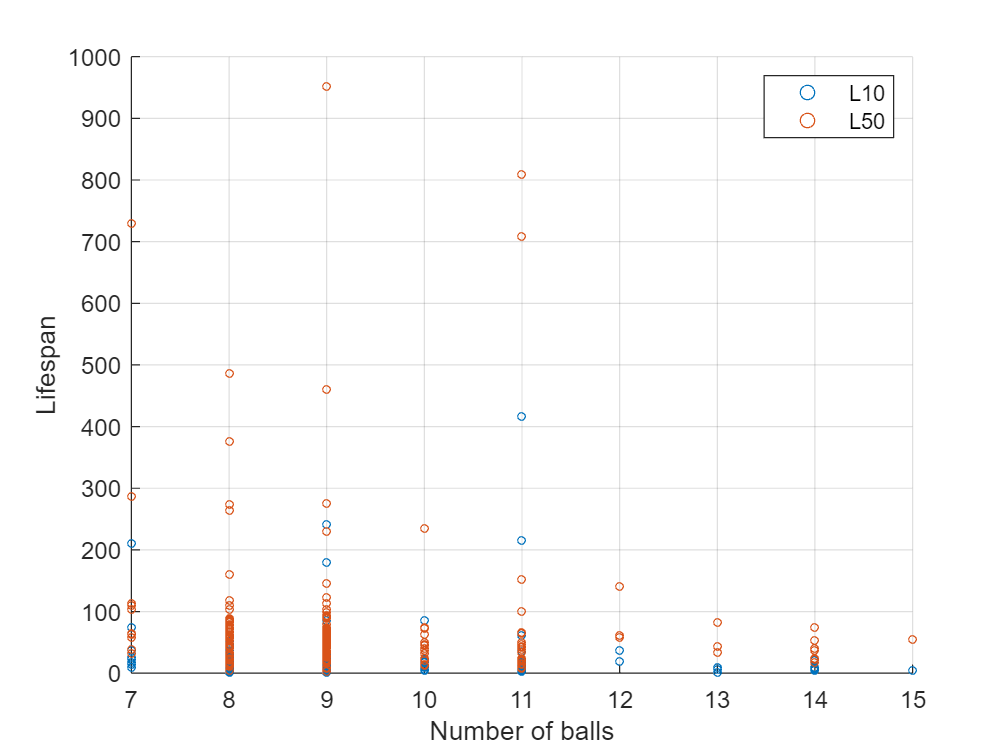

scatter(balls_number,L10,10)
hold on
scatter(balls_number,L50,10)
hold on
grid on
hold off
xlabel('Number of balls'), ylabel('Lifespan'), legend('L10','L50')

## **Sottopopolazioni**

Si analizzano ora i dati considerando come sottopopolazioni le singole aziende

## Azienda 1 - righe 1:50

company_1= table(year(1:50,1),bearings_number(1:50,1),load(1:50,1),balls_number(1:50,1), ...
    diameter(1:50,1),L10(1:50,1),L50(1:50,1),'VariableNames', ...
    {'Year','Bearings','Load','Balls','Diameter','L10','L50'})

company_1 = 50×7 table
    Year    Bearings    Load    Balls    Diameter    L10     L50 
    ____    ________    ____    _____    ________    ____    ____

    1936       24       4240      8       0.6875     19.2    84.5
    1937       20       4240      8       0.6875     26.2    74.2
    1937       14       4240      8       0.6875     11.1    68.1
    1937       19       4240      8       0.6875     11.8    66.8
    1937       18       4240      8       0.6875     13.5    79.4
    1938       21       2530      9          0.5      5.8    25.7
    1938       28       4240      8       0.6875     18.3    44.7
    1938       27       4240      8       0.6875     5.62    73.2
    1940       20       4240      8       0.6875     15.8    82.7
    1940    

### Cuscinetti - numero test effettuati

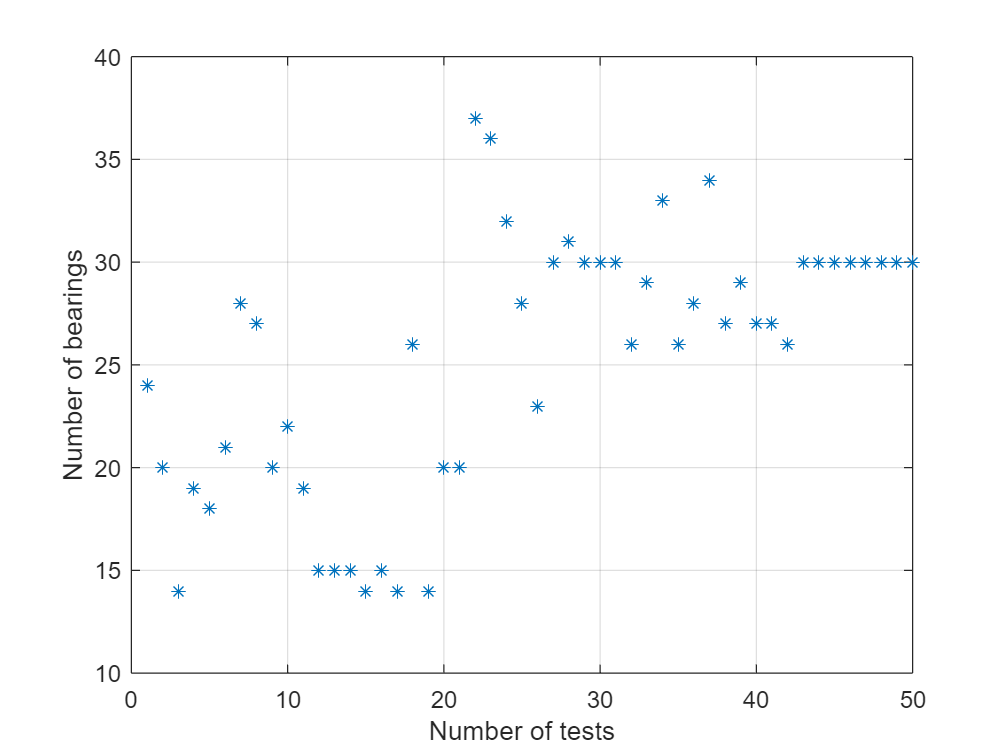

plot(1:50,bearings_number(1:50),'*'), grid on
xlabel('Number of tests'), ylabel('Number of bearings')

### Frequenza - diametri

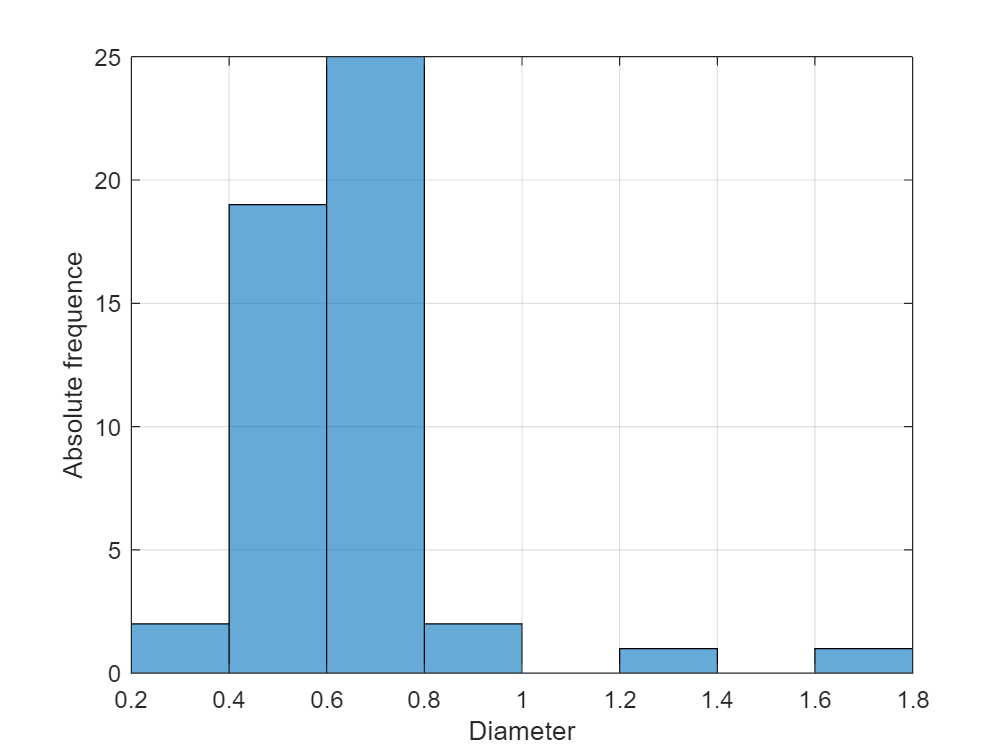

histogram(diameter(1:50,1))
xlabel('Diameter'), ylabel('Absolute frequence'), axis([0.2 1.8 0 25]), grid on

d1avg= mean(diameter(1:50,1));
d1std= std(diameter(1:50,1));

### Frequenza - numero di sfere

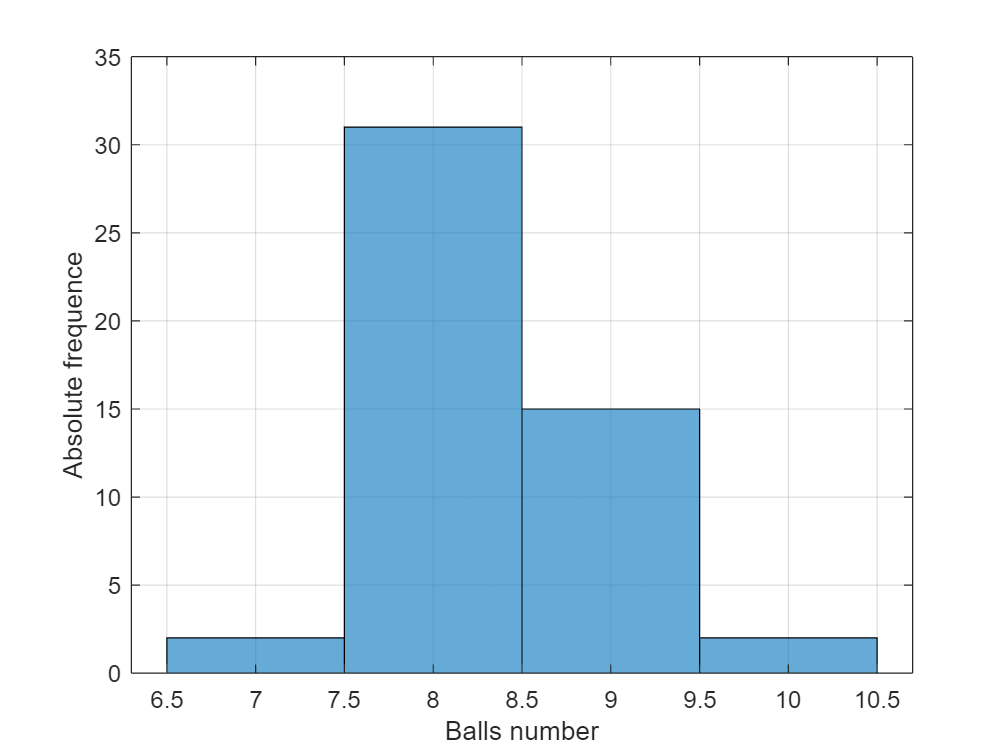

histogram(balls_number(1:50,1))
xlabel('Balls number'), ylabel('Absolute frequence'), grid on

z1avg= mean(balls_number(1:50,1));
z1std= std(balls_number(1:50,1));

### Frequenza - durata cuscinetti

#### L10

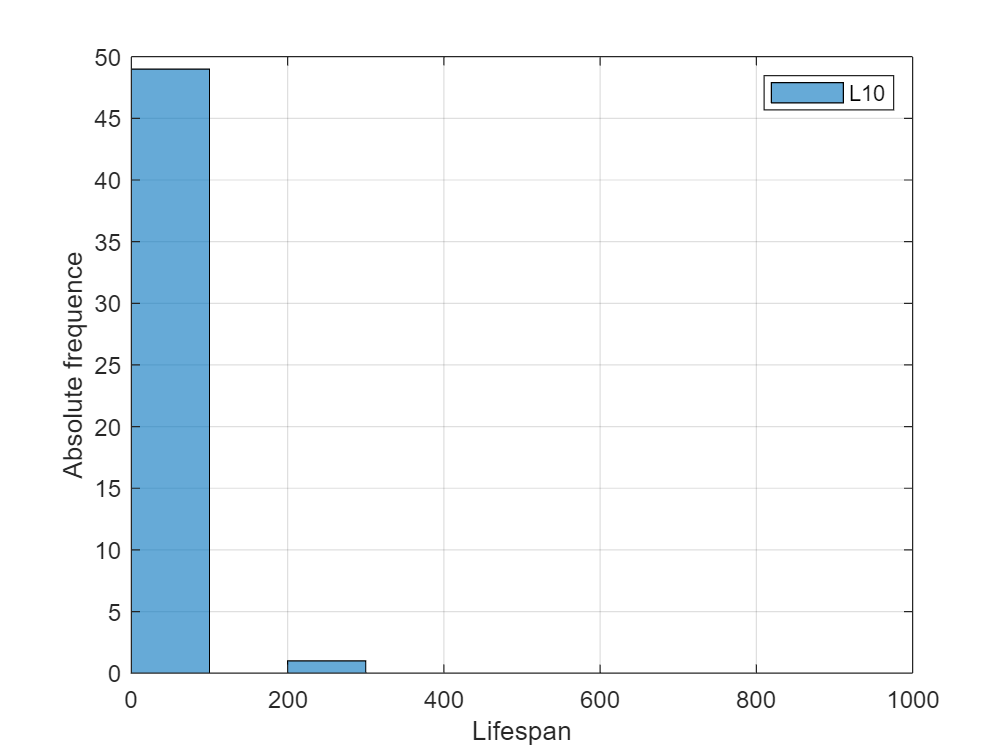

histogram(L10(1:50,1),'binwidth',100), grid on, axis([0 1000 0 50]), xlabel('Lifespan'), ylabel('Absolute frequence')
hold on, legend('L10'), hold off

l10_1avg= mean(L10(1:50,1));
l10_1std= std(L10(1:50,1));

#### L50

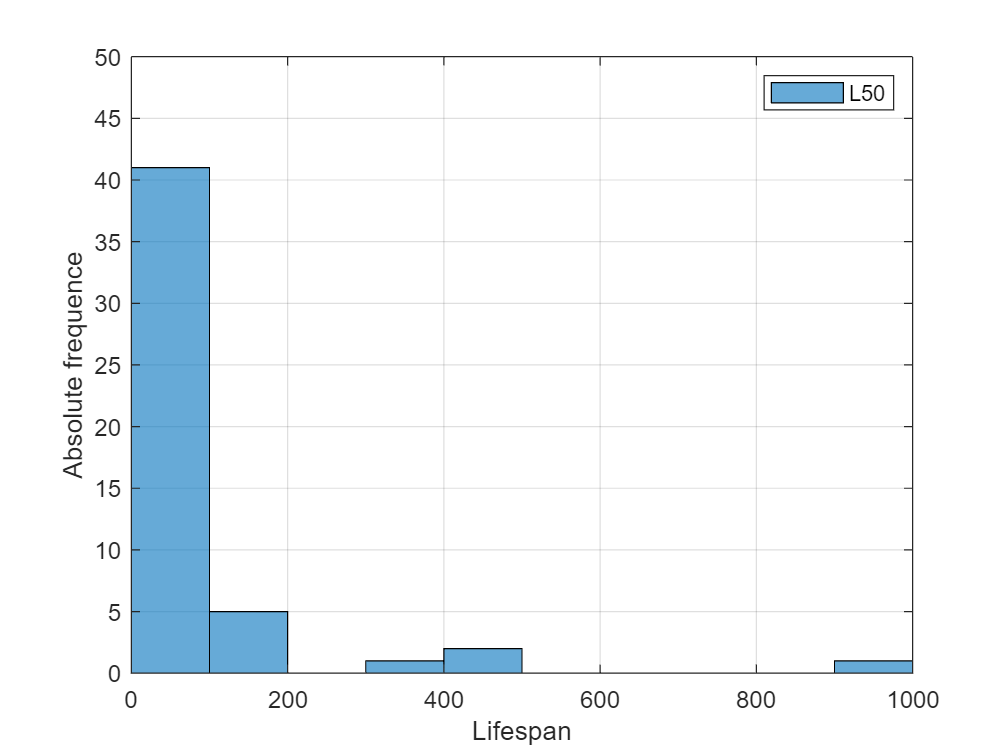

histogram(L50(1:50,1),'binwidth',100), grid on, axis([0 1000 0 50]), xlabel('Lifespan'), ylabel('Absolute frequence')
hold on, legend('L50'), hold off

l50_1avg= mean(L50(1:50,1));
l50_1std= std(L50(1:50,1));

## AZIENDA 2 - righe 51:198

company_2= table(year(51:198,1),bearings_number(51:198,1),load(51:198,1),balls_number(51:198,1), ...
    diameter(51:198,1),L10(51:198,1),L50(51:198,1),'VariableNames', ...
    {'Year','Bearings','Load','Balls','Diameter','L10','L50'})

company_2 = 148×7 table
    Year    Bearings    Load    Balls    Diameter    L10     L50 
    ____    ________    ____    _____    ________    ____    ____

    1940       19       570      10       0.1875     6.68    13.4
    1944       20       570       9       0.3125     29.8      70
    1946       23       580       9         0.25     16.3    55.1
    1946       23       580       9         0.25     28.5    69.2
    1947       23       580       9         0.25     16.4    49.3
    1943       10       665       9         0.25     10.3    40.1
    1944       10       665       9         0.25     25.7    46.4
    1942       19       580      10         0.25     9.55    39.6
    1946       33       620      10         0.25     17.9    62.1
    1947   

### Cuscinetti - numero test effettuati

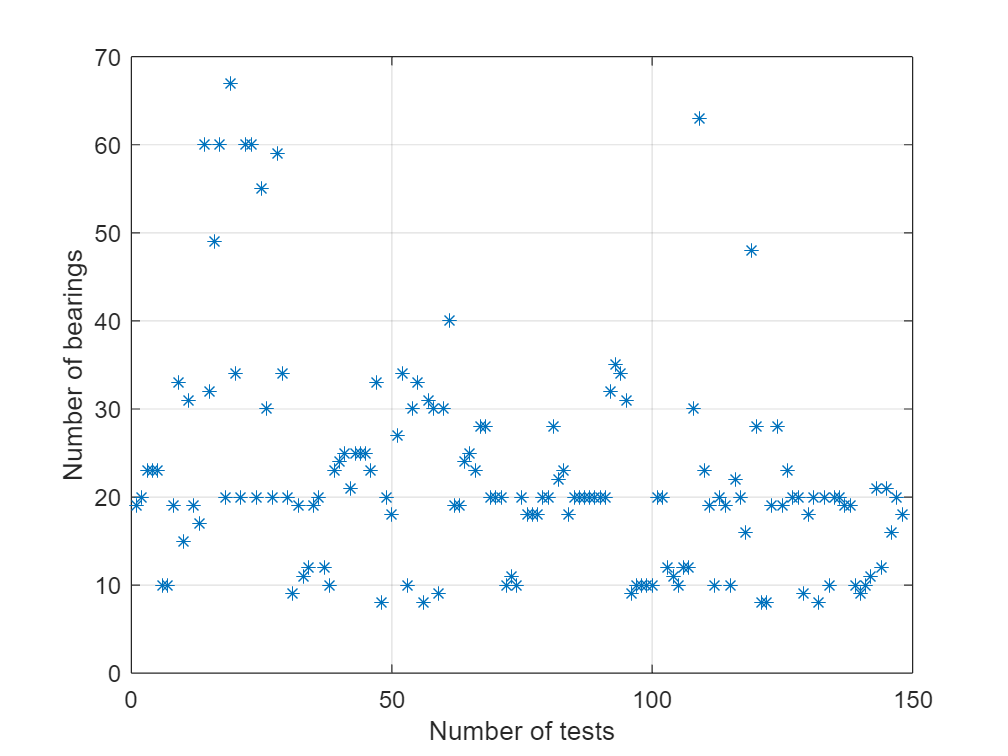

plot(1:148,bearings_number(51:198),'*'), grid on
xlabel('Number of tests'), ylabel('Number of bearings')

### Tipi di cuscinetti

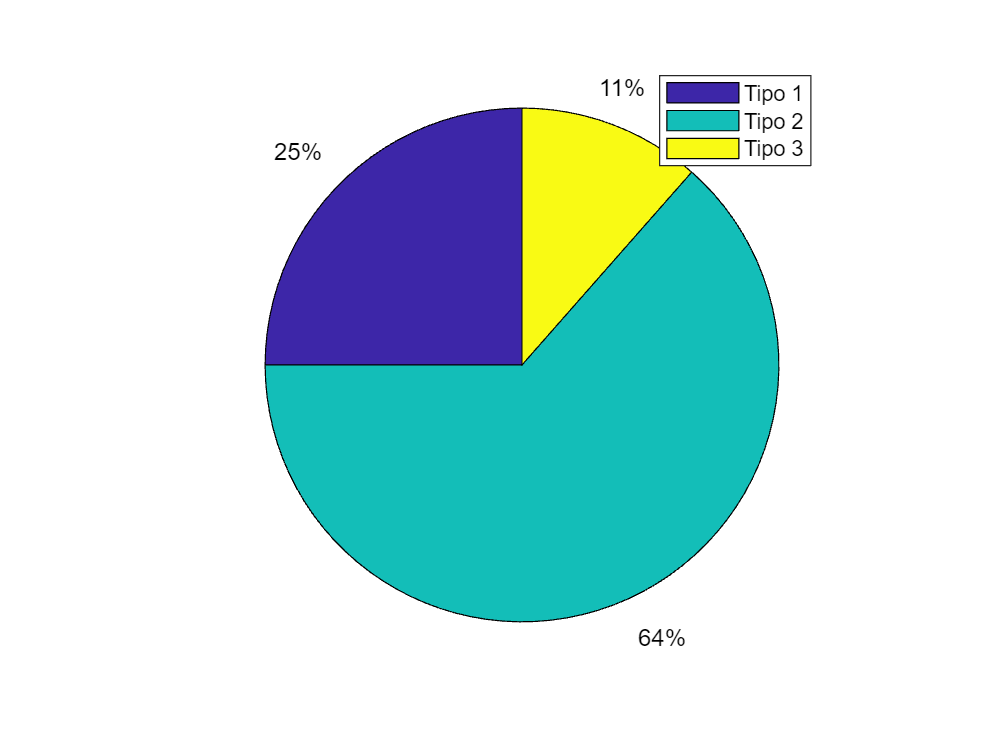

percent = {'Tipo 1','Tipo 2','Tipo 3'};
y = tabulate(Bearing_type(51:198));
y = y(:,3);

pie(y)
legend(percent)

find(Bearing_type==1);
find(Bearing_type==2);
find(Bearing_type==3);

### Durate- tipi:

#### L10

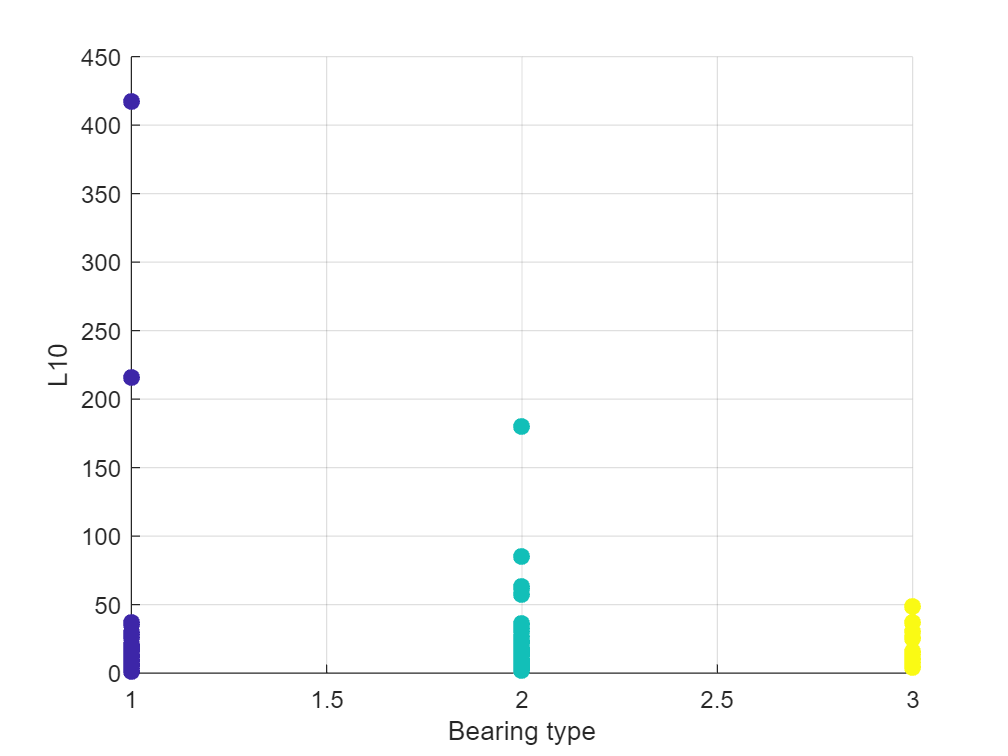

scatter(Bearing_type(51:87,1),L10(51:87,1), 'MarkerEdgeColor',[0.24 0.15 0.66],...
              'MarkerFaceColor',[0.24 0.15 0.66],...
              'LineWidth',1) %1
hold on
scatter(Bearing_type(88:181,1),L10(88:181,1), 'MarkerEdgeColor',[0.07 0.75 0.72],...
              'MarkerFaceColor',[0.07 0.75 0.72],...
              'LineWidth',1) %2
hold on
scatter(Bearing_type(182:198,1),L10(182:198,1), 'MarkerEdgeColor',[0.98 0.98 0.08],...
              'MarkerFaceColor',[0.98 0.98 0.08],...
              'LineWidth',1) %3
hold on
xlabel('Bearing type'), ylabel('L10'), grid on
hold off

#### L50

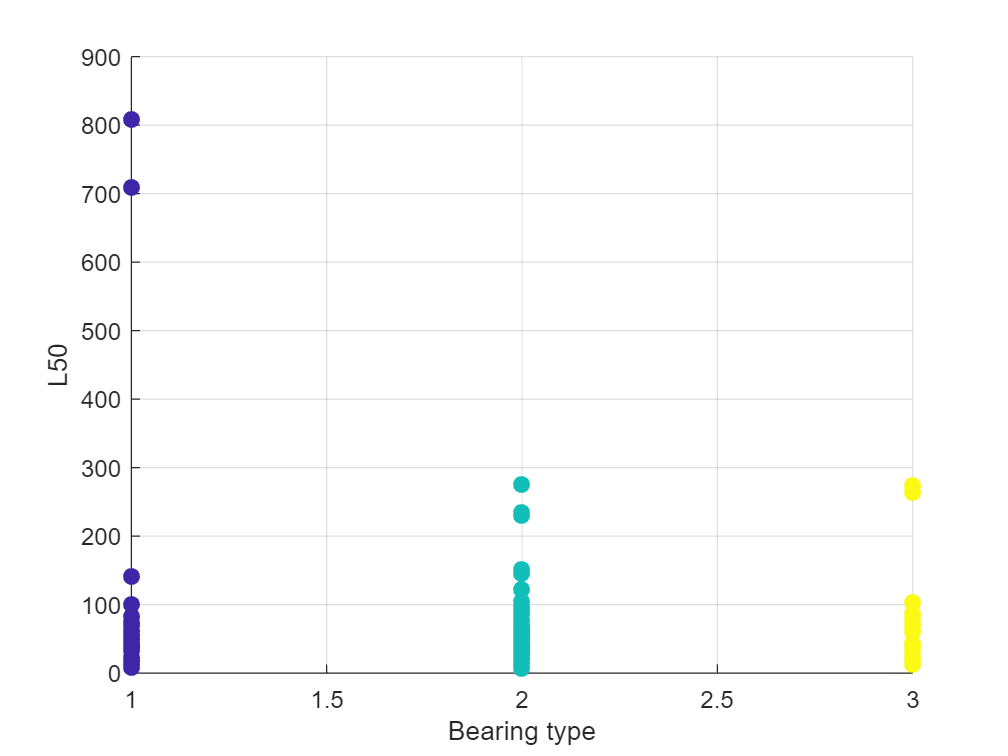

scatter(Bearing_type(51:87,1),L50(51:87,1), 'MarkerEdgeColor',[0.24 0.15 0.66],...
              'MarkerFaceColor',[0.24 0.15 0.66],...
              'LineWidth',1) %1
hold on
scatter(Bearing_type(88:181,1),L50(88:181,1), 'MarkerEdgeColor',[0.07 0.75 0.72],...
              'MarkerFaceColor',[0.07 0.75 0.72],...
              'LineWidth',1) %2
hold on
scatter(Bearing_type(182:198,1),L50(182:198,1), 'MarkerEdgeColor',[0.98 0.98 0.08],...
              'MarkerFaceColor',[0.98 0.98 0.08],...
              'LineWidth',1) %3
hold on
xlabel('Bearing type'), ylabel('L50'), grid on
hold off

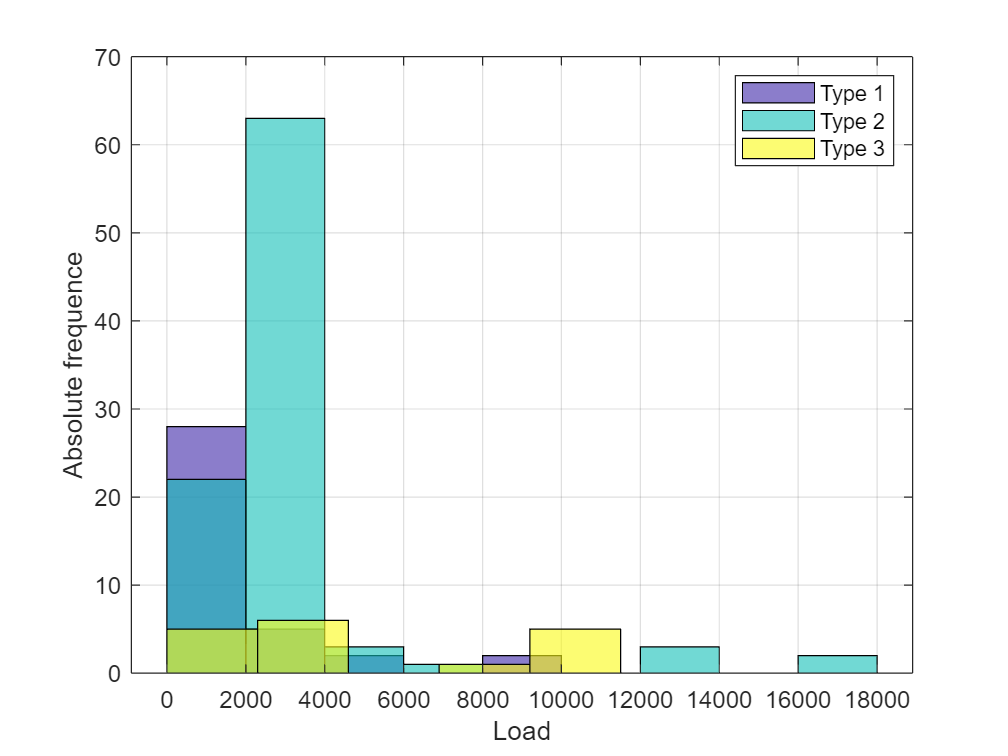

histogram(load(51:87,1), 'FaceColor', '[0.24 0.15 0.66]') %1
hold on
histogram(load(88:181,1), 'FaceColor', '[0.07 0.75 0.72]') %2
hold on
histogram(load(182:198,1),5, 'FaceColor', '[0.98 0.98 0.08]') %3
grid on
hold off
legend_1 = {'Type 1','Type 2','Type 3'};
legend(legend_1)
xlabel('Load'), ylabel('Absolute frequence')

### Diametri

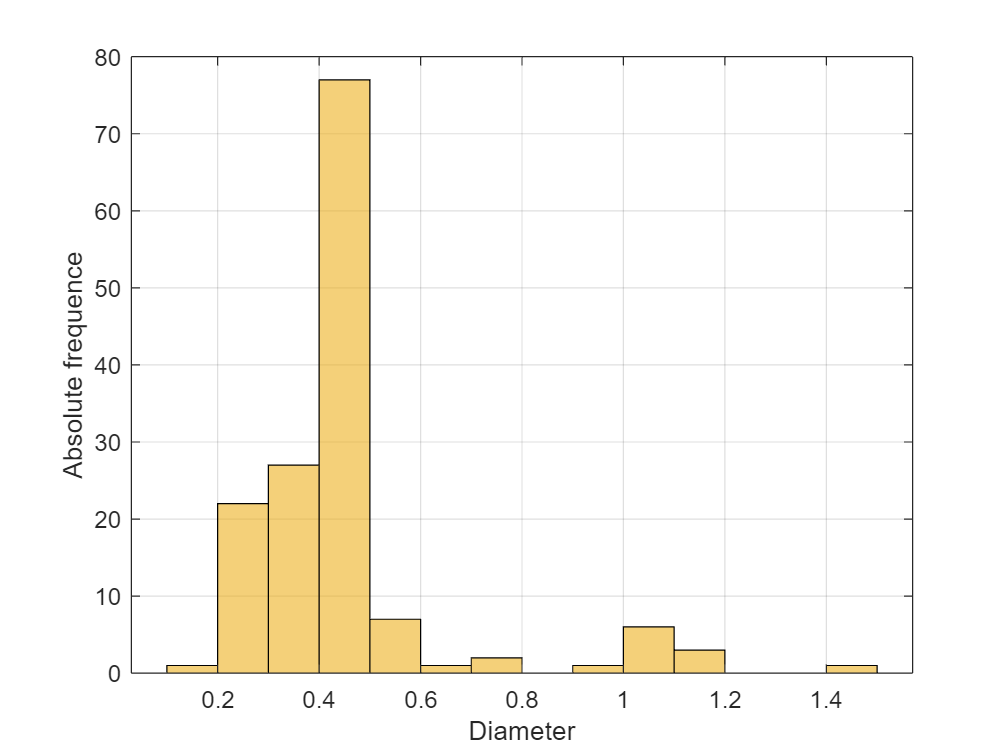

histogram(diameter(51:198,1),'FaceColor',"#EDB120")
xlabel('Diameter'), ylabel('Absolute frequence'), grid on

d2avg = mean(diameter(51:198,1));
d2std = std(diameter(51:198,1));

### Numero di sfere

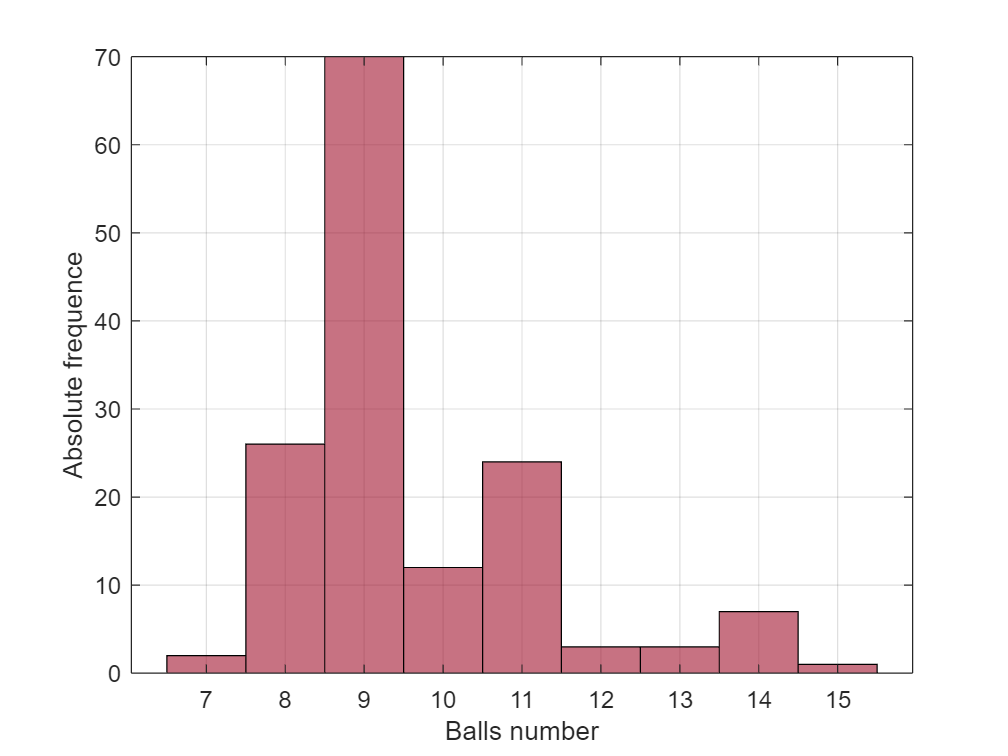

histogram(balls_number(51:198,1),'FaceColor',"#A2142F")
xlabel('Balls number'), ylabel('Absolute frequence'), grid on

z2avg = mean(balls_number(51:198,1));
z2std = std(balls_number(51:198,1));

### Durate:

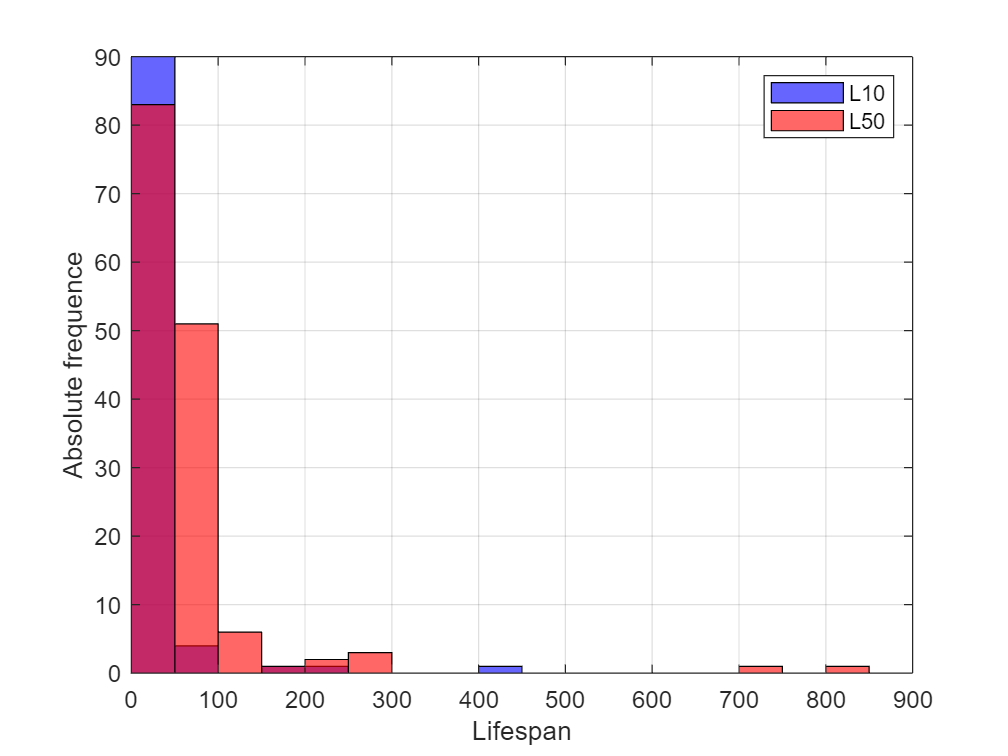

histogram(L10(51:198,1),'binwidth',50,'Facecolor','b')
hold on
histogram(L50(51:198,1),'binwidth',50,'FaceColor','r')
hold on
axis([0 900 0 90])
xlabel('Lifespan'), ylabel('Absolute frequence'), grid on
hold off
legend('L10','L50')

### L10

l10_2avg = mean(L10(51:198,1));
l10_2std = std(L10(51:198,1));

### L50

l50_2avg = mean(L50(51:198,1));
l50_2std = std(L50(51:198,1));

## AZIENDA 3 - righe 199:210

company_3= table(year(199:210,1),bearings_number(199:210,1),load(199:210,1),balls_number(199:210,1), ...
    diameter(199:210,1),L10(199:210,1),L50(199:210,1),'VariableNames', ...
    {'Year','Bearings','Load','Balls','Diameter','L10','L50'})

company_3 = 12×7 table
    Year    Bearings    Load    Balls    Diameter    L10     L50 
    ____    ________    ____    _____    ________    ____    ____

    1942       94       1580      7       0.5625     16.9    64.8
    1949       29        790      7       0.5625      211     729
    1949       35       1185      7       0.5625     74.4     287
    1940       29       1600      9          0.5     9.62    40.1
    1945       10       1600      8      0.46875     11.9    66.3
    1943        9       2275      7      0.53125     13.8      58
    1946       13       2540      8      0.46875     2.38    11.3
    1946       12       2540      8      0.46875     2.38    11.5
    1949       12       1580      7       0.5625     8.75    62.2
    1949    

### Cuscinetti - numero test effettuati

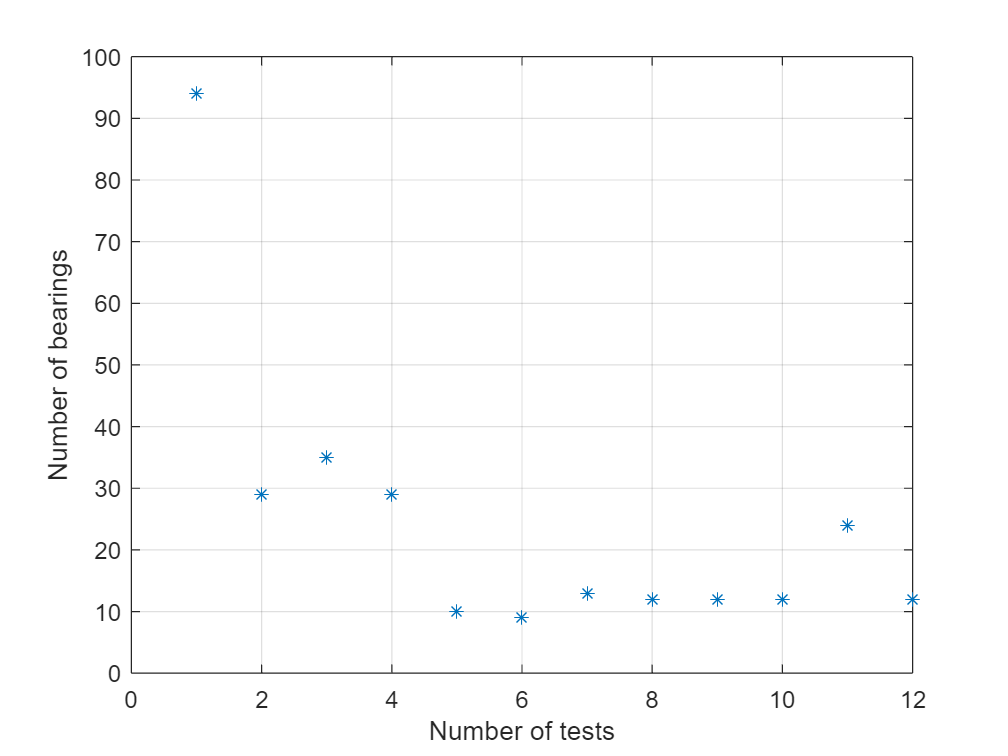

plot(1:12,bearings_number(199:210),'*')
grid on
xlabel('Number of tests'), ylabel('Number of bearings')

tot_3 = sum(bearings_number(199:210,1))

tot_3 = 291

### Frequenza - diametri

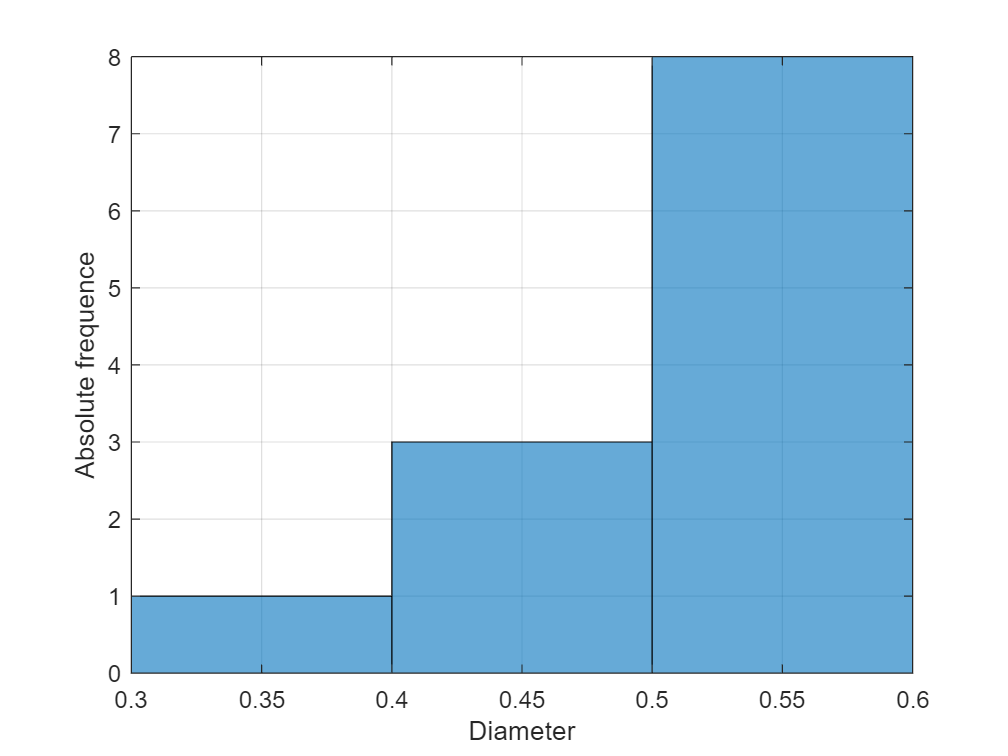

histogram(diameter(199:210,1))
xlabel('Diameter'), ylabel('Absolute frequence'), axis([0.3 0.6 0 8]), grid on

d3avg = mean(diameter(199:210,1));
d3std = std(diameter(199:210,1));

### Boxplot

Dato che il boxplot viene disegnato in riferimento alla mediana e con limiti primo e terzo quartile, può essere uno strumento visivo per determinare se un dato campione ha una distribuzione approssimabile con una normale.

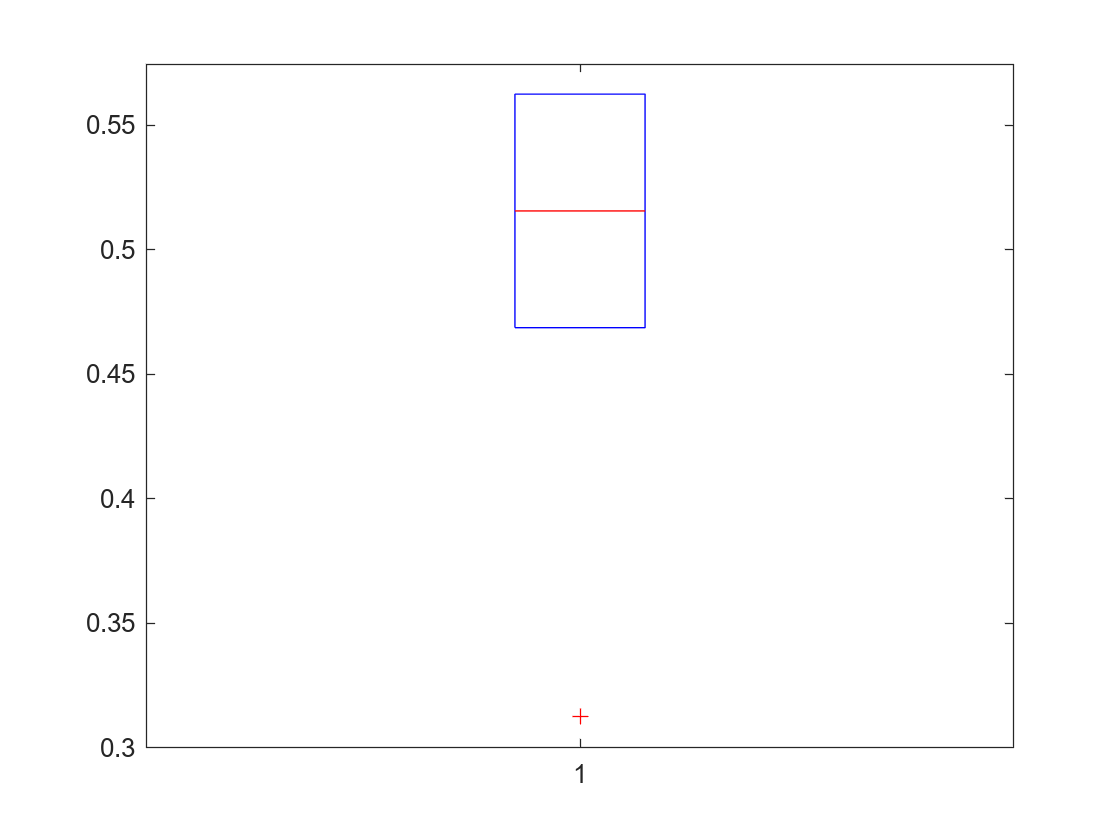

boxplot(diameter(199:210,1))

Da questo boxplot si può vedere come la distribuzione sia pressoché simmetrica rispetto alla mediana. È presente un outlier.

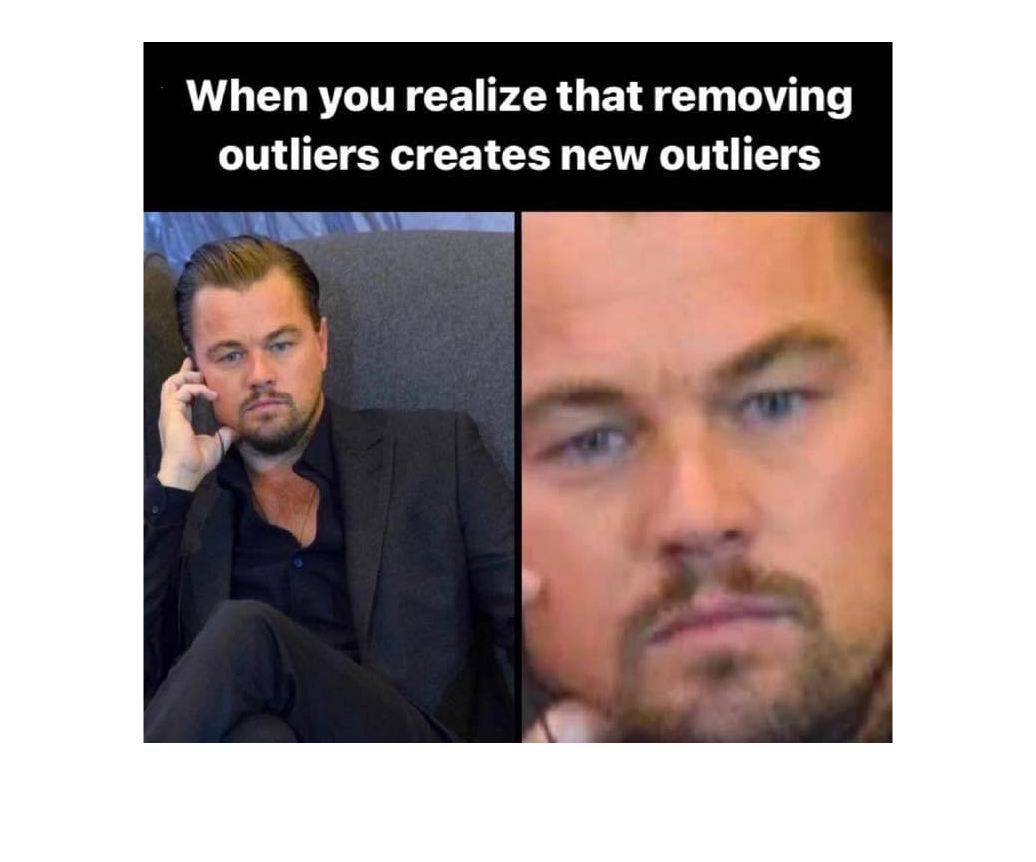

imshow('m1.jpg')

### Frequenza numero di sfere

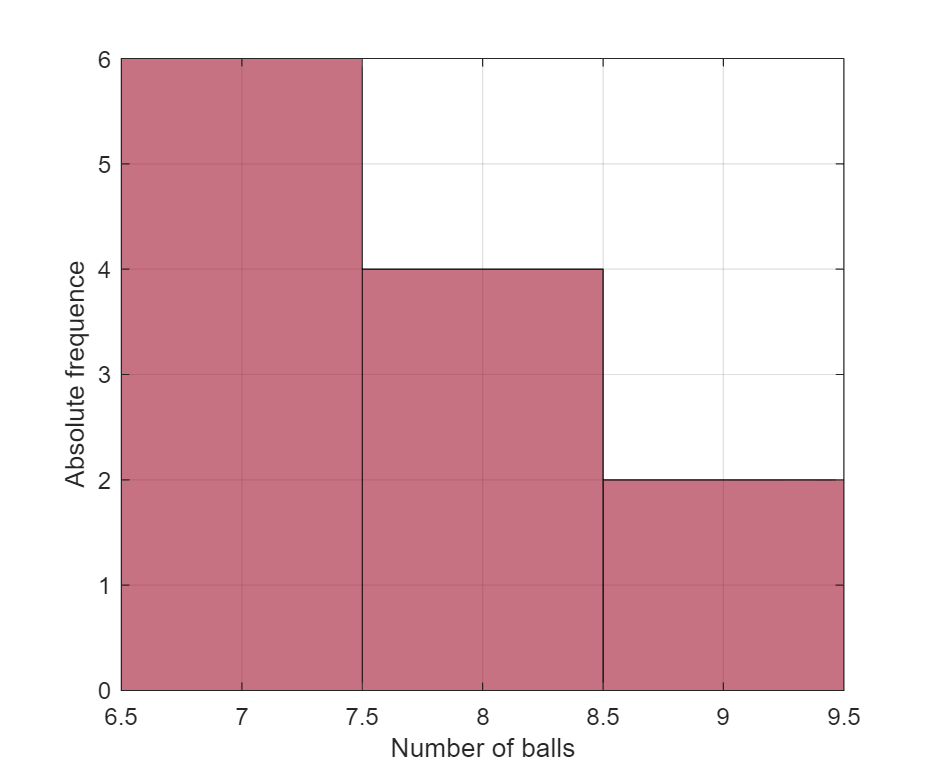

histogram(balls_number(199:210,1),'FaceColor',"#A2142F")
xlabel('Number of balls'), ylabel('Absolute frequence'), axis([6.5 9.5 0 6])
grid on

z3avg = mean(balls_number(199:210,1));
z3std = std(balls_number(199:210,1));

### Boxplot

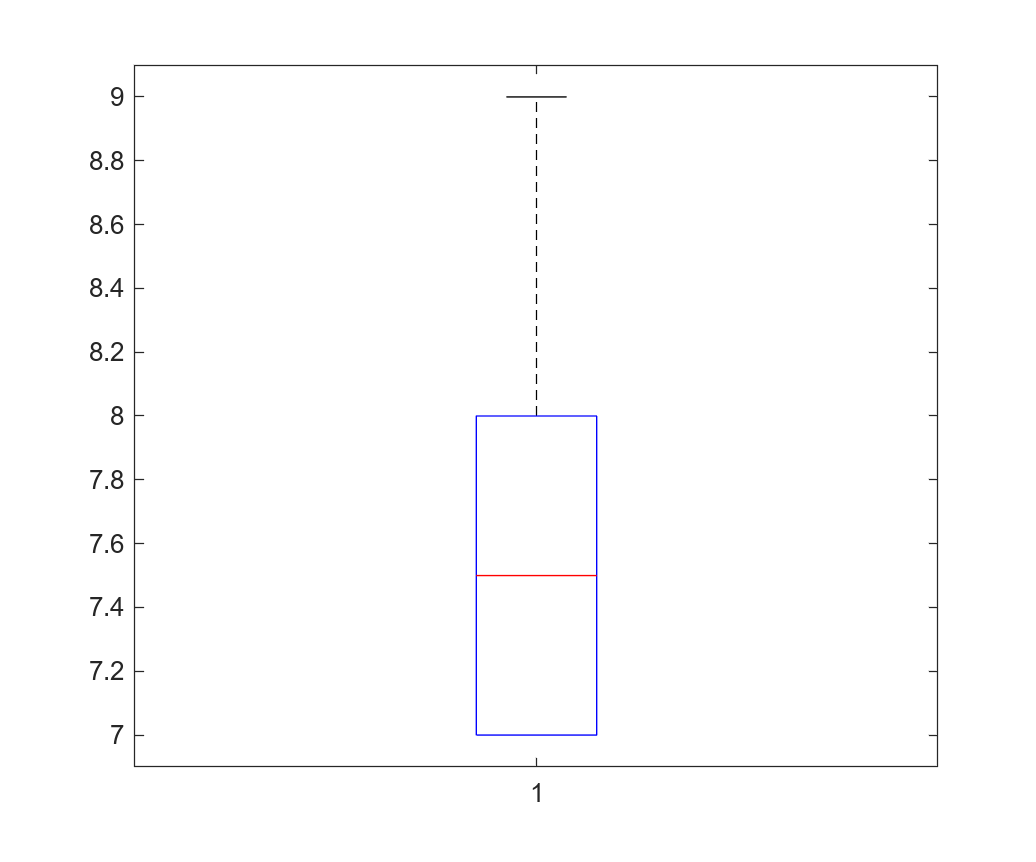

boxplot(balls_number(199:210,1))

### Durata cuscinetti

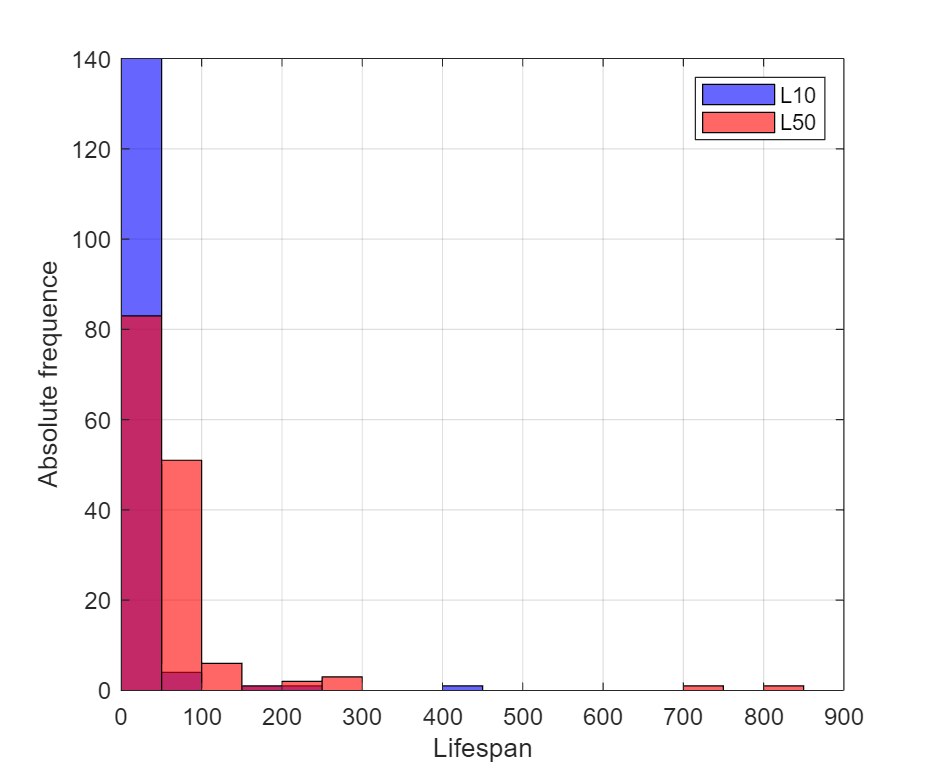

histogram(L10(51:198,1),'binwidth',50,'Facecolor','b')
hold on
histogram(L50(51:198,1),'FaceColor','r')
hold on
axis([0 900 0 140])
xlabel('Lifespan'), ylabel('Absolute frequence'), grid on
hold off
legend('L10','L50')

### L10

l10_3avg = mean(L10(51:198,1));
l10_3std = std(L10(51:198,1));

### L50

l50_3avg = mean(L50(51:198,1));
l50_3std = std(L50(51:198,1));

### Carichi sui cuscinetti

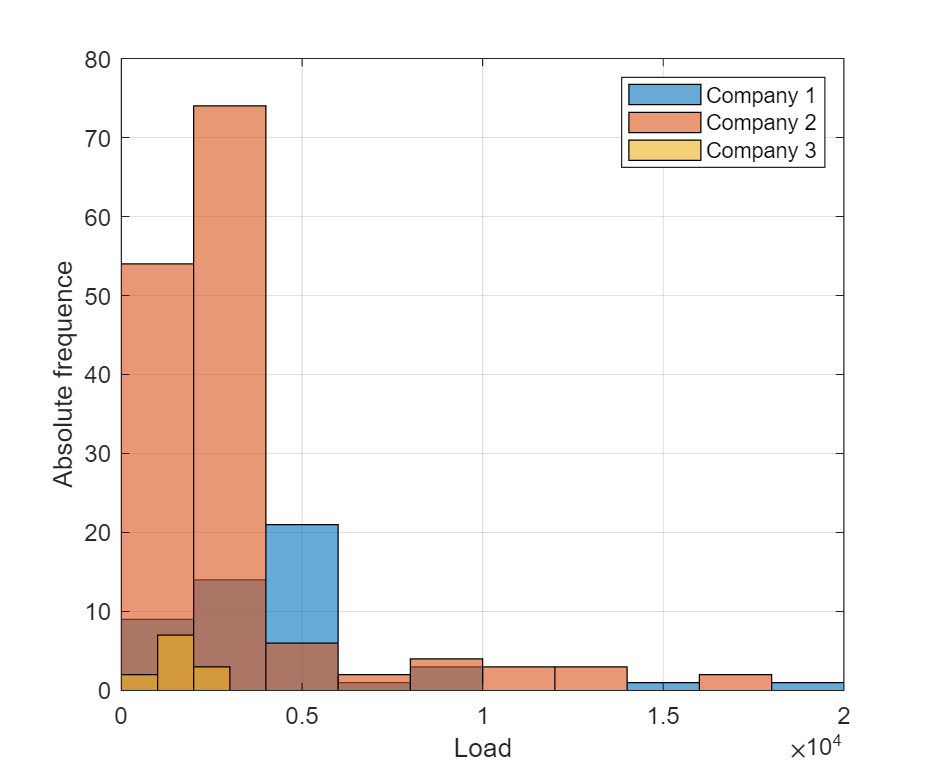

histogram(load(1:50,1),'binwidth',2000)
hold on
histogram(load(51:198,1))
hold on
histogram(load(199:210,1))
hold on
grid on, xlabel('Load'), ylabel('Absolute frequence'), axis([0 20000 0 80])
labels = {'Company 1','Company 2','Company 3'};
legend(labels)
hold off

pavg = mean(load);
pstd = std(load);

**Azienda 1**

p1avg = mean(load(1:50,1));
p1std = std(load(1:50,1));

**Azienda 2**

p2avg = mean(load(51:198,1));
p2std = std(load(51:198,1));

**Azienda 3**

p3avg = mean(load(199:210,1));
p3std = std(load(199:210,1));

Come si vede dagli istogrammi, i cuscinetti delle prime due aziende hanno una distribuzione che è ben approssimata da una normale, complice anche l'avere più di 30 osservazioni nel campione. Per la terza il discorso è leggermente diverso: le osservazioni sono minori (il campione è formato da 12 elementi). La distribuzione verrà comunque considerata normale.

# **CAMPIONAMENTO - Inferenza statistica**

Preso un campione di confronto generato casualmente di numerosità pari a 30, si calcola l'intervallo di confidenza per la media vera in relazione alla media campionaria e alla varianza campionaria. 

## Stima della media

### Diametro

Il campione di confronto è trovato con *randperm(n,k), *che fornisce k numeri casuali interi da 1 a n. Si userà $\alpha =0\ldotp 05\Longrightarrow Z_{\frac{\alpha }{2}} =1\ldotp 96$.

%cfr_rand= randperm(210,30);
cfr_stored= [172 190	27	209	131	20	57	112	194	202	32	201	207	96	157	28	82	177	153	184	125	7 160 175 127 141 137 72 120 31];
avg_d_samp= mean(diameter(cfr_stored));
d_linf_samp= avg_d_samp-(1.96*(std(diameter)/sqrt(30)));
d_lsup_samp= avg_d_samp+(1.96*(std(diameter)/sqrt(30)));

### Numero di sfere

avg_nballs_samp= mean(balls_number(cfr_stored));
z_linf_samp= avg_nballs_samp-(1.96*(std(balls_number)/sqrt(30)));
z_lsup_samp= avg_nballs_samp+(1.96*(std(balls_number)/sqrt(30)));

### Durata

#### L10

avg_l10_samp= mean(L10(cfr_stored));
l10__linf_samp= avg_l10_samp-(1.96*(std(L10)/sqrt(30)));
l10__lsup_samp= avg_l10_samp+(1.96*(std(L10)/sqrt(30)));

#### L50

avg_l50_samp= mean(L50(cfr_stored));
l50__linf_samp= avg_l50_samp-(1.96*(std(L50)/sqrt(30)));
l50__lsup_samp= avg_l50_samp+(1.96*(std(L50)/sqrt(30)));

### Carico

avg_p_samp= mean(load(cfr_stored));
p__linf_samp= avg_p_samp-(1.96*(std(load)/sqrt(30)));
p__lsup_samp= avg_p_samp+(1.96*(std(load)/sqrt(30)));

### Tabella dati cfr

avgs = [avg_d_samp;round(avg_nballs_samp);avg_l10_samp;avg_l50_samp;avg_p_samp];
linfs = [d_linf_samp;round(z_linf_samp);l10__linf_samp;l50__linf_samp;p__linf_samp];
lsups = [d_lsup_samp;round(z_lsup_samp);l10__lsup_samp;l50__lsup_samp;p__lsup_samp];
avgss = table(avgs,linfs,lsups,'VariableNames',{'Sample mean','Lim inf','Lim sup'},'RowNames',{'Diameter','Balls n.','L10','L50','Load'})

avgss = 5×3 table
                Sample mean    Lim inf    Lim sup
                ___________    _______    _______

    Diameter      0.52812      0.44846    0.60779
    Balls n.            9            8         10
    L10            18.081         3.39     32.772
    L50            68.265       25.181     111.35
    Load           3039.9       1967.7     4112.1


### Medie sottopopolazioni S1 e S2

Si prendono ora n=15 elementi per formare due sottopopolazioni in base alle prime due aziende. 

n= 15;
cp1= 50;
cp2= 148; 
s1= randperm(cp1,n);
s2= randperm(cp2,n);

Possiamo supporre la **varianza nota** (pari a quella calcolata sul campione di 30) e calcolare la media campionaria dei due campioni.

Scegliamo come grado di confidenza **0.95** ($\alpha =0\ldotp 05\Longrightarrow Z_{\frac{\alpha }{2}} =1\ldotp 96$).

### Diametri

d_s1= diameter(1:50,1);
d_s2= diameter(51:198,1);
sd_avg1= mean(d_s1(s1));
sd_avg2= mean(d_s2(s2));
dleft= -1.96*sqrt(d1std^2/cp1 + d2std^2/cp2) + (sd_avg1+sd_avg2);
dright= 1.96*sqrt(d1std^2/cp1 + d2std^2/cp2) + (sd_avg1+sd_avg2);

### Numero di sfere

z_s1= balls_number(1:50,1);
z_s2= balls_number(51:198,1);
sz_avg1= mean(z_s1(s1));
sz_avg2= mean(z_s2(s2));
zleft= -1.96*sqrt(z1std^2/cp1 + z2std^2/cp2) + (sz_avg1+sz_avg2);
zright= 1.96*sqrt(z1std^2/cp1 + z2std^2/cp2) + (sz_avg1+sz_avg2);

### Durata

**L10**

l10_s1= L10(1:50,1);
l10_s2= L10(51:198,1);
sl10_avg1= mean(l10_s1(s1));
sl10_avg2= mean(l10_s2(s2));
l10left= -1.96*sqrt(l10_1std^2/cp1 + l10_2std^2/cp2) + (sl10_avg1+sl10_avg2);
l10right= 1.96*sqrt(l10_1std^2/cp1 + l10_2std^2/cp2) + (sl10_avg1+sl10_avg2);

**L50**

l50_s1= L50(1:50,1);
l50_s2= L50(51:198,1);
sl50_avg1= mean(l50_s1(s1));
sl50_avg2= mean(l50_s2(s2));
l50left= -1.96*sqrt(l50_1std^2/cp1 + l50_2std^2/cp2) + (sl50_avg1+sl50_avg2);
l50right= 1.96*sqrt(l50_2std^2/cp1 + l50_2std^2/cp2) + (sl50_avg1+sl50_avg2);

### Carico

load_s1= load(1:50,1);
load_s2= load(51:198,1);
sp_avg1= mean(load_s1(s1));
sp_avg2= mean(load_s2(s2));
pleft= -1.96*sqrt(p1std^2/cp1 + p2std^2/cp2) + (sp_avg1+sp_avg2);
pright= 1.96*sqrt(p1std^2/cp1 + p2std^2/cp2) + (sp_avg1+sp_avg2);

### Tabella S1 e S2

left= [dleft;round(zleft);l10left;l50left;pleft];
right= [dright;round(zright);l10right;l50right;pright];
intervals = table(left,right,'VariableNames',{'Left','Right'},'RowNames',{'Diameters','Balls n.','L10','L50','Load'})

intervals = 5×2 table
                  Left     Right 
                 ______    ______

    Diameters    1.0579    1.2005
    Balls n.         17        18
    L10           34.76    58.928
    L50          97.569     173.9
    Load         6165.7    8185.4


# **TEST D'IPOTESI**

## **Test della media**

Presa una popolazione casuale di n=30 dall'azienda 2, si vuole vedere quanto la media si distacca da quella "vera". 

Prendiamo ad esempio la durata al 90% di success rate (la più usata in ambito industriale tra le due).

$H_0$: $\bar{x} =3\ldotp 0835\times {10}^3$, ipotesi nulla

$H_1$: $\bar{x} \not= 3\ldotp 0835\times {10}^3$, ipotesi alternativa

Assumiamo la **varianza nota** e la popolazione distribuita in modo **normale** (la numerosità del campione ce lo permette). Il test sarà bilatero a partire dalla statistica su $\mu_0 :Z_0 =\frac{\bar{x} -\mu_0 }{\frac{\sigma }{\sqrt{n}}}$

pavg; %media "vera"
disp(pstd); %varianza 

   2.9962e+03



disp(p2avg); %media sottopopolazione azienda 2

   2.8444e+03



Preso $\alpha =0\ldotp 05\Longrightarrow$$Z_{\frac{\alpha }{2}} =1\ldotp 96$

nstd_0 = (p2avg-pavg)/(pstd/sqrt(30)) %standardizzata

nstd_0 = -0.4370

Dato che $Z_0 \in \left\lbrack -Z_{\frac{\alpha }{2}} ,Z_{\frac{\alpha }{2}} \right\rbrack$ l'ipotesi nulla può essere accettata.

## p-value

Per $Z=-0\ldotp 4370$ dalle tavole di ripartizione della normale si ha un'area a SX pari a $0\ldotp 334$. Il **p-value, **che è il doppio di quest'area è pari a $0\ldotp 67>\alpha$.

# **ANALISI DI REGRESSIONE**

Si cercherà un modello di regressione lineare multipla per approssimare la surata L10 dei cuscinetti (quella più usata in ambito industriale) in cui le variabili sono **Z, D, P**: numero di sfere, diametro e carico. Il modello sarà $L_{10h} =\beta_{1\;} Z+\beta_2 \;D+\beta_3 \;\;P\;+\beta_0 \;\ldotp$ Verrà usata la funzione *fitlm(X,y) *che fornisce un modello di regressione lineare per le y, con i dati X.

linearL10= fitlm([balls_number,diameter,load],L10)

linearL10 = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)      -39.266       26.582    -1.4772       0.14115
    x1                3.6185       2.0746     1.7442      0.082624
    x2                121.43       37.107     3.2725     0.0012501
    x3             -0.011051    0.0027149    -4.0706    6.6829e-05


Number of observations: 210, Error degrees of freedom: 206
Root Mean Squared Error: 39.5
R-squared: 0.0859,  Adjusted R-Squared: 0.0726
F-statistic vs. constant model: 6.45, p-value = 0.00034

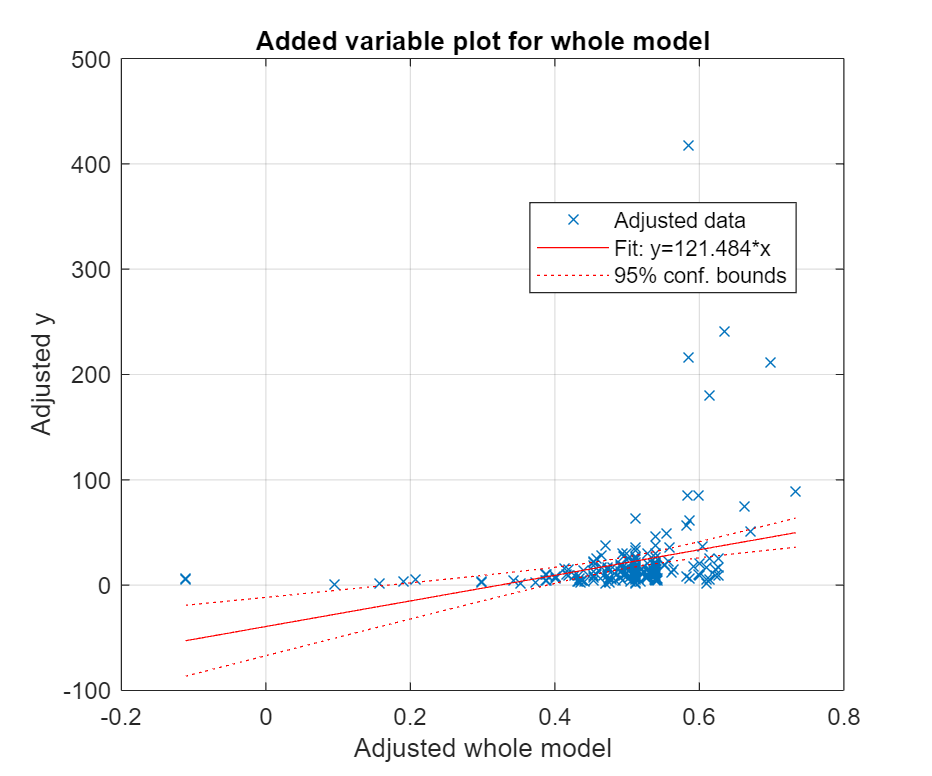

plot(linearL10), grid on

Si può vedere che il coefficiente di determinazione $r^2$ è molto basso, per cui il modello lineare cercato non è molto efficace.

Proviamo invece a correlare la durata $L_{10h}$ con il solo carico equivalente applicato:

linearL10_01= fitlm(load,L10)

linearL10_01 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)        29.632        4.0011    7.4059    3.1949e-12
    x1             -0.0026823    0.00093169    -2.879     0.0044066


Number of observations: 210, Error degrees of freedom: 208
Root Mean Squared Error: 40.4
R-squared: 0.0383,  Adjusted R-Squared: 0.0337
F-statistic vs. constant model: 8.29, p-value = 0.00441

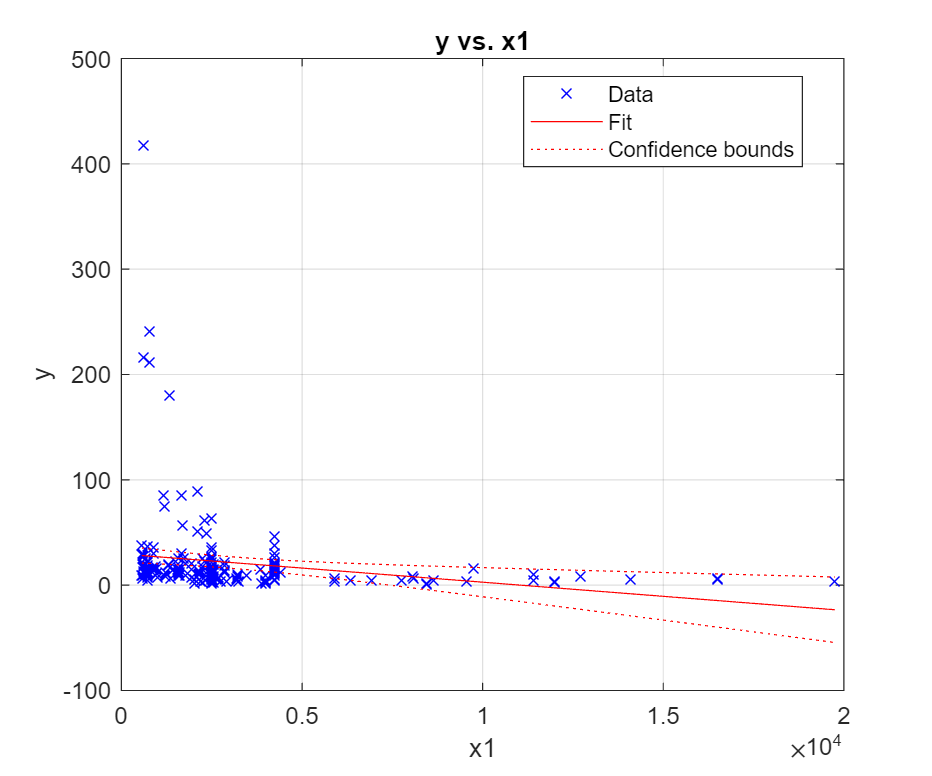

plot(linearL10_01), grid on

La dispersione nella zona iniziale fa sì che anche questo modello sia poco efficace. Questo è dovuto al fatto che la legge che esprime la durata in funzione del carico è esponenziale. Si può provare allora un modello di regressione *lineare generalizzata, *sulla base del seguente modello logaritmico:


$$\ln \left(L_{10h} \right)=\alpha +\beta_1 \ln \left(Z\right)+\beta_2 \ln \left(D\right)+\beta_3 \ln \left(P\right)$$


logL10 = log(L10);
logZ = log(balls_number);
logD = log(diameter);
logP = log(load);
logfitL10 = fitlm([logZ,logD,logP],logL10)

logfitL10 = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     19.561      1.4645     13.357    1.0062e-29
    x1               1.449     0.37489     3.8651    0.00014881
    x2              3.8236     0.39156     9.7651    9.3948e-19
    x3             -2.2471     0.18644    -12.053    1.1521e-25


Number of observations: 210, Error degrees of freedom: 206
Root Mean Squared Error: 0.69
R-squared: 0.455,  Adjusted R-Squared: 0.447
F-statistic vs. constant model: 57.2, p-value = 6.02e-27

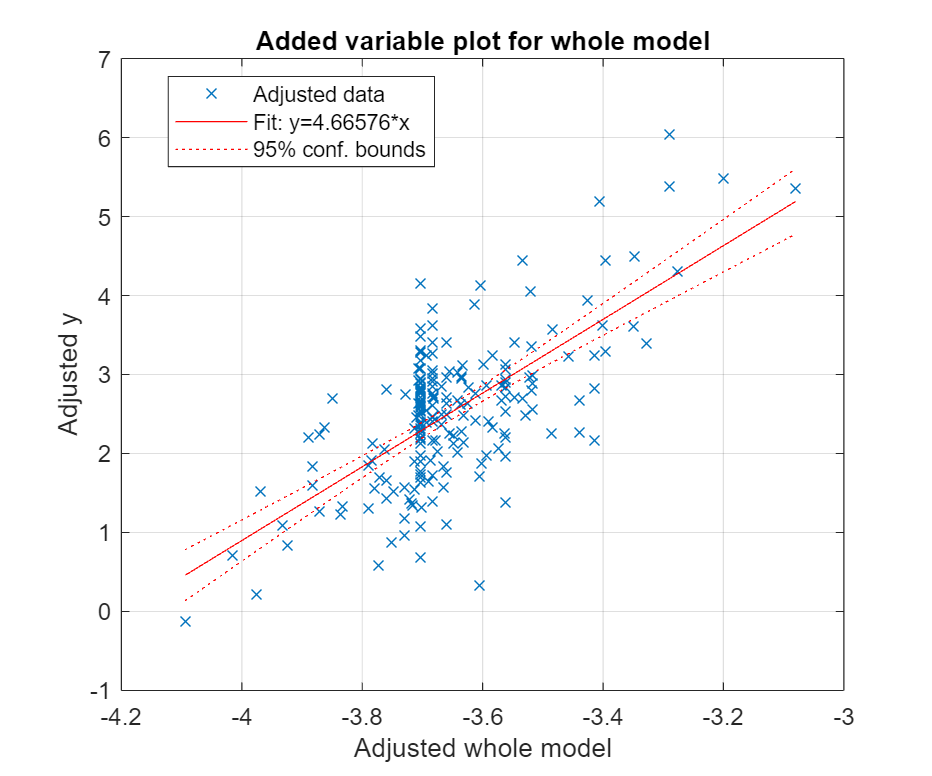

plot(logfitL10), grid on

Il modello non è comunque rappresentato al meglio ma ha un **adjusted r-squared **di 10 volte superiore al modello precedente. Proviamo a correlare linearmente solo il logaritmo di L10 con il logaritmo del carico equivalente:

logfitL10_1 = fitlm(logP,logL10)

logfitL10_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)      6.6113     0.58313     11.338    1.6379e-23
    x1             -0.53069    0.075149    -7.0618    2.4209e-11


Number of observations: 210, Error degrees of freedom: 208
Root Mean Squared Error: 0.835
R-squared: 0.193,  Adjusted R-Squared: 0.19
F-statistic vs. constant model: 49.9, p-value = 2.42e-11

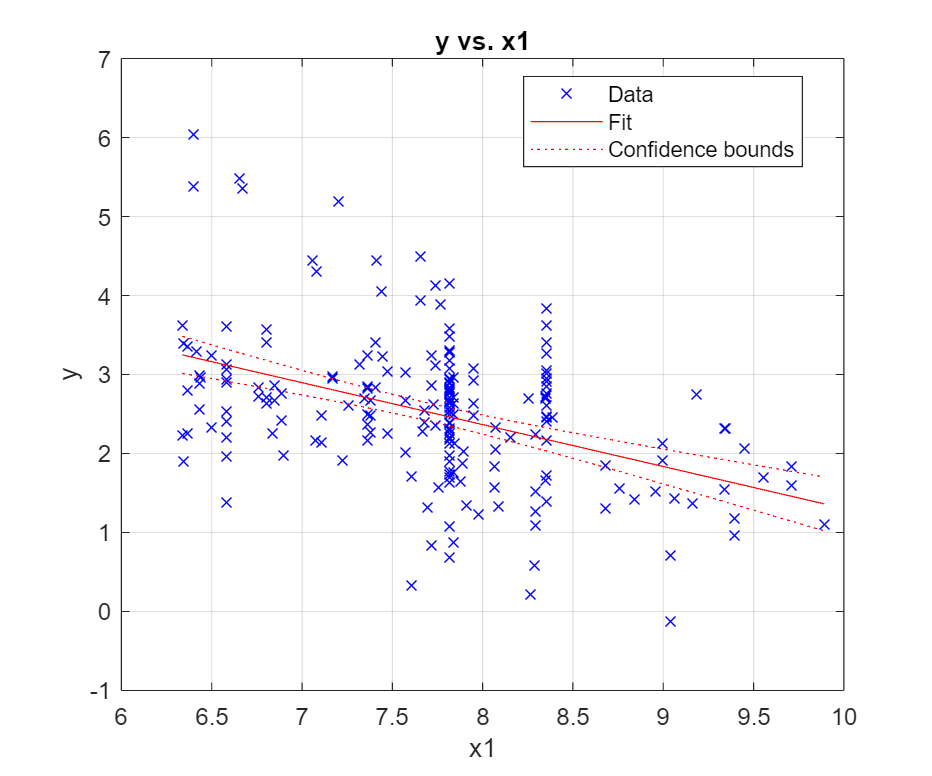

plot(logfitL10_1), grid on

È risultato anche peggiore.

# **TEST DEL **$\chi^2$

Vogliamo studiare la correlazione della durata L10 rispetto all'azienda produttrice, usando il test del **chi-quadro**:

$H_0$: la posizione della durata (sopra o sotto la media) è correlata all'azienda, ipotesi nulla

$H_1$: la posizione della durata (sopra o sotto la media)  non è correlata all'azienda, ipotesi alternativa

Si devono ora trasformare le variabili in categoriche. La durata verrà suddivisa in due classi, una di durate superiori alla media e una di durate inferiori alla media:

below_avg1 = find(L10(1:50,1)<L10avg);
above_avg1 = find(L10(1:50,1)>=L10avg);
category_11 = L10(below_avg1,:);
category_21 = L10(above_avg1,:);
size11 = size(category_11);
size21 = size(category_21);

below_avg2 = find(L10(51:198,1)<L10avg);
above_avg2 = find(L10(51:198,1)>=L10avg);
category_12 = L10(below_avg2,:);
category_22 = L10(above_avg2,:);
size12 = size(category_12);
size22 = size(category_22);

below_avg3 = find(L10(199:210,1)<L10avg);
above_avg3 = find(L10(199:210,1)>=L10avg);
category_13 = L10(below_avg3,:);
category_23 = L10(above_avg3,:);
size13 = size(category_13);
size23 = size(category_23);

below_avg = [size11(1,1), size12(1,1), size13(1,1),];
above_avg = [size21(1,1), size22(1,1), size23(1,1),];
colsums = [sum(below_avg(1,:)),sum(above_avg(1,:))];
below_avg = [size11(1,1), size12(1,1), size13(1,1), colsums(1,1)]';
above_avg = [size21(1,1), size22(1,1), size23(1,1), colsums(1,2)]';
rowsums = below_avg+above_avg   ;
chi_table = table(below_avg,above_avg,rowsums,'VariableNames',{'Below avg','Above avg', 'Row sum'},'RowNames',{'Company 1','Company 2','Company 3','Column sum'})

chi_table = 4×3 table
                  Below avg    Above avg    Row sum
                  _________    _________    _______

    Company 1         41           9           50  
    Company 2        119          29          148  
    Company 3          8           4           12  
    Column sum       168          42          210  


writetable(chi_table, 'tavola_chi2.xlsx')
stat_cfr = readtable('tavola_chi2.xlsx','Range','H1:I4', 'VariableNamingRule', 'preserve')

stat_cfr = 3×2 table
    Expected below    Expected above
    ______________    ______________

          9.8               2.1     
         83.9              20.4     
          0.5               0.2     


x_sq = sum(((([below_avg(1:3,:), above_avg(1:3,:)]-table2array(stat_cfr)).^2)./(table2array(stat_cfr))),'all')

x_sq = 325.0118

Il numero di gdl sarà $\textrm{dof}\;=\left(r-1\right)\left(c-1\right)=2$. Scegliamo un grado di confidenza pari a $0\ldotp 95$, che implica $\alpha =0\ldotp 05\Longrightarrow \chi_{0\ldotp 95,\;2}^2 =0\ldotp 1026$ 

Dato che $x_{\textrm{sq}} >\chi_{0\ldotp 95,\;2}^2$ dobbiamo rifiutare l'ipotesi $H_0$.

# **CONCLUSIONI**

Dopo aver presentato i dati si è visto come sia legittimo assumere che la media campionaria della durata di una sottopopolazione randomica sia quella *vera *attraverso il test d'ipotesi bilatero. Si è successivamente provato ad approssimare la distribuzione attraverso un modello lineare a più variabili che però è risultato poco adeguato poiché il modello che lega durata e carico equivalente è esponenziale. Infatti, un successivo modello di *regressione generalizzata *in cui la scala è logaritmica si è dimostrato più efficace. Infine si è voluta testare l'indipendenza tra la durata di un cuscinetto (nella fattispecie che sia sopra o sotto la media) e l'azienda produttrice, da cui si è ottenuto che le due variabili *non *sono indipendenti. In futuro si potrebbe provare ad utilizzare un campionamento non più *casuale semplice,* data l'eterogeneità dei gruppi ma, appunto, casuale a gruppi o stratificato (in modo da ottenere risultati migliori nell'analisi di regressione, magari ottenendo un modello più accurato ma valido in un *dominio più ristretto*).